EKF - Single feature tracking

Step 1: Connect UART ports.

ports = serialportlist

ports = 1×28 string array
    "/dev/cu.FreeBuds3"    "/dev/tty.FreeBuds3"    "/dev/cu.Bluetooth-Incoming-Port"    "/dev/tty.Bluetooth-Incoming-Port"    "/dev/cu.usbserial-0001"    "/dev/tty.usbserial-0001"    "/dev/cu.SLAB_USBtoUART"    "/dev/tty.SLAB_USBtoUART"    "/dev/cu.SLAB_USBtoUART9"    "/dev/tty.SLAB_USBtoUART9"    "/dev/cu.usbserial-10"    "/dev/tty.usbserial-10"    "/dev/cu.usbserial-2"    "/dev/tty.usbserial-2"    "/dev/cu.SLAB_USBtoUART5"    "/dev/tty.SLAB_USBtoUART5"    "/dev/cu.usbserial-6"    "/dev/tty.usbserial-6"    "/dev/cu.SLAB_USBtoUART4"    "/dev/tty.SLAB_USBtoUART4"    "/dev/cu.usbserial-1"    "/dev/tty.usbserial-1"    "/dev/cu.SLAB_USBtoUART7"    "/dev/tty.SLAB_USBtoUART7"    "/dev/cu.usbserial-8"    "/dev/tty.usbserial-8"    "/dev/cu.SLAB_USBtoUART11"    "/dev/tty.SLAB_USBtoUART11"


openmv1=0;
openmv2=0;
openmv3=0;
openmv4=0;
openmv5=0;
openmv6=0;

openmv1 = serialport('/dev/tty.usbserial-0001',115200)

openmv1 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-0001"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv2 = serialport('/dev/tty.usbserial-1',115200)

openmv2 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-1"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv3 = serialport('/dev/tty.usbserial-2',115200)

openmv3 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-2"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv4 = serialport('/dev/tty.usbserial-6',115200)

openmv4 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-6"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv5 = serialport('/dev/tty.usbserial-8',115200)

openmv5 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-8"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv6 = serialport('/dev/tty.usbserial-10',115200)

openmv6 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-10"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


Step 2: Intrinisc parameters

openmv1.write('INT','string')
openmv2.write('INT','string')
openmv3.write('INT','string')
openmv4.write('INT','string')
openmv5.write('INT','string')
openmv6.write('INT','string')

camID1 = extractAfter(openmv1.readline(),'0')

camID1 = "3"

camID2 = extractAfter(openmv2.readline(),'0')

camID2 = "2"

camID3 = extractAfter(openmv3.readline(),'0')

camID3 = "1"

camID4 = extractAfter(openmv4.readline(),'0')

camID4 = "4"

camID5 = extractAfter(openmv5.readline(),'0')

camID5 = "5"

camID6 = extractAfter(openmv6.readline(),'0')

camID6 = "6"


filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt1 = file1_1.cameraParams;
calibInt1 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt2 = file1_1.cameraParams;
calibInt2 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt3 = file1_1.cameraParams;
calibInt3 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt4 = file1_1.cameraParams;
calibInt4 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt5 = file1_1.cameraParams;
calibInt5 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt6 = file1_1.cameraParams;
calibInt6 = file1_2.cameraParams;

cInt1

cInt1 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [20×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.2039
                 ReprojectionErrors: [35×2×20 double]
                  ReprojectedPoints: [35×2×20 double]

   Calibration Settings
                        NumPatterns: 20
                  DetectedKeypoints: [35×20 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 3
       EstimateTangentialDistortion: 0


cInt2

cInt2 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [14×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.3511
                 ReprojectionErrors: [35×2×14 double]
                  ReprojectedPoints: [35×2×14 double]

   Calibration Settings
                        NumPatterns: 14
                  DetectedKeypoints: [35×14 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


calibInt1

calibInt1 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [14×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.1221
                 ReprojectionErrors: [35×2×14 double]
                  ReprojectedPoints: [35×2×14 double]

   Calibration Settings
                        NumPatterns: 14
                  DetectedKeypoints: [35×14 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 3
       EstimateTangentialDistortion: 0


calibInt2

calibInt2 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [18×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.2068
                 ReprojectionErrors: [35×2×18 double]
                  ReprojectedPoints: [35×2×18 double]

   Calibration Settings
                        NumPatterns: 18
                  DetectedKeypoints: [35×18 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


Step 3: Extrinsic parameters

3a: Set world points

F1_B = [-0.12 0.12]; %RED
F2_B = [0.12 -0.12]; %GREEN
F3_B = [0.12 0.12]; %BLUE
F4_B = [-0.12 -0.12]; %PURPLE
F5_B = [-0.12 0]; %WHITE
F6_B = [0 0.12]; %CYAN

worldPoints = [F1_B;F2_B;F3_B;F4_B;F5_B];%F6_B];

3b(1): Get pixel location data of worldpoints - RGB

openmv1.write('EXT_RGB','string')
flush(openmv1)
extData1 = openmv1.readline()

extData1 = "219,151,138,196,212,211,152,142,186,145"

myData1 = str2double(split(extData1,','))

myData1 =    219
   151
   138
   196
   212
   211
   152
   142
   186
   145


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints1_RGB = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv2.write('EXT_RGB','string')
flush(openmv2)
extData2 = openmv2.readline()

extData2 = "189,181,146,124,124,165,201,137,196,157"

myData2 = str2double(split(extData2,','))

myData2 =    189
   181
   146
   124
   124
   165
   201
   137
   196
   157


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints2_RGB = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]

openmv3.write('EXT_RGB','string')
flush(openmv3)
extData1 = openmv3.readline()

extData1 = "127,129,117,195,167,164,82,157,105,141"

myData1 = str2double(split(extData1,','))

myData1 =    127
   129
   117
   195
   167
   164
    82
   157
   105
   141


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints3_RGB = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv4.write('EXT_RGB','string')
flush(openmv4)
extData2 = openmv4.readline()

extData2 = "163,176,157,101,113,139,205,129,185,153"

myData2 = str2double(split(extData2,','))

myData2 =    163
   176
   157
   101
   113
   139
   205
   129
   185
   153


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints4_RGB = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]

openmv5.write('EXT_RGB','string')
flush(openmv5)
extData1 = openmv5.readline()

extData1 = "152,215,209,170,154,168,212,215,182,214"

myData1 = str2double(split(extData1,','))

myData1 =    152
   215
   209
   170
   154
   168
   212
   215
   182
   214


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints5_RGB = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv6.write('EXT_RGB','string')
flush(openmv6)
extData2 = openmv6.readline()

extData2 = "210,157,127,126,145,178,183,112,197,133"

myData2 = str2double(split(extData2,','))

myData2 =    210
   157
   127
   126
   145
   178
   183
   112
   197
   133


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints6_RGB = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]


%NORMALIZE IMAGE POINTS > 0<=imagePoint*<=1
normRGB_imagePoints1 = [imagePoints1_RGB(:,1)/calibInt1.ImageSize(2) imagePoints1_RGB(:,2)/calibInt1.ImageSize(1)]

normRGB_imagePoints1 =     0.6844    0.6292
    0.4313    0.8167
    0.6625    0.8792
    0.4750    0.5917
    0.5813    0.6042


normRGB_imagePoints2 = [imagePoints2_RGB(:,1)/calibInt2.ImageSize(2) imagePoints2_RGB(:,2)/calibInt2.ImageSize(1)]

normRGB_imagePoints2 =     0.5906    0.7542
    0.4562    0.5167
    0.3875    0.6875
    0.6281    0.5708
    0.6125    0.6542



normRGB_imagePoints3 = [imagePoints3_RGB(:,1)/calibInt3.ImageSize(2) imagePoints3_RGB(:,2)/calibInt3.ImageSize(1)]

normRGB_imagePoints3 =     0.3969    0.5375
    0.3656    0.8125
    0.5219    0.6833
    0.2562    0.6542
    0.3281    0.5875


normRGB_imagePoints4 = [imagePoints4_RGB(:,1)/calibInt4.ImageSize(2) imagePoints4_RGB(:,2)/calibInt4.ImageSize(1)]

normRGB_imagePoints4 =     0.5094    0.7333
    0.4906    0.4208
    0.3531    0.5792
    0.6406    0.5375
    0.5781    0.6375



normRGB_imagePoints5 = [imagePoints5_RGB(:,1)/calibInt5.ImageSize(2) imagePoints5_RGB(:,2)/calibInt5.ImageSize(1)]

normRGB_imagePoints5 =     0.4750    0.8958
    0.6531    0.7083
    0.4813    0.7000
    0.6625    0.8958
    0.5687    0.8917


normRGB_imagePoints6 = [imagePoints6_RGB(:,1)/calibInt6.ImageSize(2) imagePoints6_RGB(:,2)/calibInt6.ImageSize(1)]

normRGB_imagePoints6 =     0.6562    0.6542
    0.3969    0.5250
    0.4531    0.7417
    0.5719    0.4667
    0.6156    0.5542



openmv1.write('EXT_RGB_SUCCESS','string');
openmv2.write('EXT_RGB_SUCCESS','string');
openmv3.write('EXT_RGB_SUCCESS','string');
openmv4.write('EXT_RGB_SUCCESS','string');
openmv5.write('EXT_RGB_SUCCESS','string');
openmv6.write('EXT_RGB_SUCCESS','string');

3b(2): Get pixel location data of worldpoints - 

flush(openmv1)
flush(openmv2)
flush(openmv3)
flush(openmv4)
flush(openmv5)
flush(openmv6)

openmv1.write('EXT_GRAY','string')
extData1 = openmv1.readline()

extData1 = "304,275,373,288,441,300,271,395,425,422,0.974659"

myData1 = str2double(split(extData1,','))

myData1 =    304
   275
   373
   288
   441
   300
   271
   395
   425
   422


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints1_GRAY = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv2.write('EXT_GRAY','string')
extData2 = openmv2.readline()

extData2 = "290,246,409,269,395,313,247,331,380,362,0.97371"

myData2 = str2double(split(extData2,','))

myData2 =    290
   246
   409
   269
   395
   313
   247
   331
   380
   362


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints2_GRAY = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]

openmv3.write('EXT_GRAY','string')
extData1 = openmv3.readline()

extData1 = "257,256,210,282,159,309,336,329,233,394,0.974659"

myData1 = str2double(split(extData1,','))

myData1 =    257
   256
   210
   282
   159
   309
   336
   329
   233
   394


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints3_GRAY = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv4.write('EXT_GRAY','string')
extData2 = openmv4.readline()

extData2 = "314,201,416,260,225,278,373,304,326,352,0.974659"

myData2 = str2double(split(extData2,','))

myData2 =    314
   201
   416
   260
   225
   278
   373
   304
   326
   352


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints4_GRAY = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]

openmv5.write('EXT_GRAY','string')
extData1 = openmv5.readline()

extData1 = "308,336,421,340,303,428,366,431,431,432,0.974659"

myData1 = str2double(split(extData1,','))

myData1 =    308
   336
   421
   340
   303
   428
   366
   431
   431
   432


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints5_GRAY = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv6.write('EXT_GRAY','string')
extData2 = openmv6.readline()

extData2 = "372,219,252,252,396,266,423,315,290,356,0.974659"

myData2 = str2double(split(extData2,','))

myData2 =    372
   219
   252
   252
   396
   266
   423
   315
   290
   356


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints6_GRAY = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]


%NORMALIZE IMAGE POINTS > 0<=imagePoint*<=1
normGRAY_imagePoints1 = [imagePoints1_GRAY(:,1)/cInt1.ImageSize(2) imagePoints1_GRAY(:,2)/cInt1.ImageSize(1)]

normGRAY_imagePoints1 =     0.4750    0.5729
    0.5828    0.6000
    0.6891    0.6250
    0.4234    0.8229
    0.6641    0.8792


normGRAY_imagePoints2 = [imagePoints2_GRAY(:,1)/cInt2.ImageSize(2) imagePoints2_GRAY(:,2)/cInt2.ImageSize(1)]

normGRAY_imagePoints2 =     0.4531    0.5125
    0.6391    0.5604
    0.6172    0.6521
    0.3859    0.6896
    0.5938    0.7542


normGRAY_imagePoints3 = [imagePoints3_GRAY(:,1)/cInt3.ImageSize(2) imagePoints3_GRAY(:,2)/cInt3.ImageSize(1)]

normGRAY_imagePoints3 =     0.4016    0.5333
    0.3281    0.5875
    0.2484    0.6438
    0.5250    0.6854
    0.3641    0.8208


normGRAY_imagePoints4 = [imagePoints4_GRAY(:,1)/cInt4.ImageSize(2) imagePoints4_GRAY(:,2)/cInt4.ImageSize(1)]

normGRAY_imagePoints4 =     0.4906    0.4188
    0.6500    0.5417
    0.3516    0.5792
    0.5828    0.6333
    0.5094    0.7333


normGRAY_imagePoints5 = [imagePoints5_GRAY(:,1)/cInt5.ImageSize(2) imagePoints5_GRAY(:,2)/cInt5.ImageSize(1)]

normGRAY_imagePoints5 =     0.4813    0.7000
    0.6578    0.7083
    0.4734    0.8917
    0.5719    0.8979
    0.6734    0.9000


normGRAY_imagePoints6 = [imagePoints6_GRAY(:,1)/cInt6.ImageSize(2) imagePoints6_GRAY(:,2)/cInt6.ImageSize(1)]

normGRAY_imagePoints6 =     0.5813    0.4562
    0.3937    0.5250
    0.6188    0.5542
    0.6609    0.6562
    0.4531    0.7417


openmv1.write('EXT_GRAY_SUCCESS','string');
openmv2.write('EXT_GRAY_SUCCESS','string');
openmv3.write('EXT_GRAY_SUCCESS','string');
openmv4.write('EXT_GRAY_SUCCESS','string');
openmv5.write('EXT_GRAY_SUCCESS','string');
openmv6.write('EXT_GRAY_SUCCESS','string');

%C1__________________
imagePoints1_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints1(k,:) - normGRAY_imagePoints1(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints1_distorted(k,:) = imagePoints1_GRAY(pos,:);
end

imagePoints1_undistorted = zeros(5,2);
for k = 1:5
    imagePoints1_undistorted(k,:) = undistortPoints(imagePoints1_distorted(k,:),cInt1);
end
    imagePoints1_undistorted = imagePoints1_undistorted(1:5,:)

imagePoints1_undistorted =   442.1970  301.0440
  267.1830  402.3430
  428.5271  432.2342
  303.6722  275.2876
  373.0678  288.2732


extrinsics_1 = estimateExtrinsics(imagePoints1_undistorted,worldPoints,cInt1.Intrinsics);
camPose_1 = extr2pose(extrinsics_1)

camPose_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.5471 -0.0358 0.9061]
                 R: [3×3 double]
                 A: [4×4 double]



%C2___________________
imagePoints2_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints2(k,:) - normGRAY_imagePoints2(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints2_distorted(k,:) = imagePoints2_GRAY(pos,:);
end

imagePoints2_undistorted = zeros(5,2);
for k = 1:5
    imagePoints2_undistorted(k,:) = undistortPoints(imagePoints2_distorted(k,:),cInt2);
end
imagePoints2_undistorted = imagePoints2_undistorted(1:5,:)

imagePoints2_undistorted =   380.3493  362.6602
  289.7666  245.8130
  245.8409  331.5651
  409.4099  268.9006
  395.2435  313.1197


extrinsics_2 = estimateExtrinsics(imagePoints2_undistorted,worldPoints,cInt2.Intrinsics);
camPose_2 = extr2pose(extrinsics_2)

camPose_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.2814 0.7452 0.8535]
                 R: [3×3 double]
                 A: [4×4 double]



%C3_____________________________
imagePoints3_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints3(k,:) - normGRAY_imagePoints3(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints3_distorted(k,:) = imagePoints3_GRAY(pos,:)
end

imagePoints3_distorted =    257   256
     0     0
     0     0
     0     0
     0     0


imagePoints3_distorted =    257   256
   233   394
     0     0
     0     0
     0     0


imagePoints3_distorted =    257   256
   233   394
   336   329
     0     0
     0     0


imagePoints3_distorted =    257   256
   233   394
   336   329
   159   309
     0     0


imagePoints3_distorted =    257   256
   233   394
   336   329
   159   309
   210   282



imagePoints3_undistorted = zeros(5,2);
for k = 1:5
    imagePoints3_undistorted(k,:) = undistortPoints(imagePoints3_distorted(k,:),cInt3);
end
    imagePoints3_undistorted = imagePoints3_undistorted(1:5,:)

imagePoints3_undistorted =   255.6763  256.3719
  226.2309  403.0094
  335.7201  330.2896
  147.3941  313.7461
  205.5195  283.6463


extrinsics_3 = estimateExtrinsics(imagePoints3_undistorted,worldPoints,cInt3.Intrinsics);
camPose_3 = extr2pose(extrinsics_3)

camPose_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.6137 -0.4664 0.9594]
                 R: [3×3 double]
                 A: [4×4 double]



%C4_____________________________
imagePoints4_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints4(k,:) - normGRAY_imagePoints4(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints4_distorted(k,:) = imagePoints4_GRAY(pos,:);
end

imagePoints4_undistorted = zeros(5,2);
for k = 1:5
    imagePoints4_undistorted(k,:) = undistortPoints(imagePoints4_distorted(k,:),cInt4);
end
    imagePoints4_undistorted = imagePoints4_undistorted(1:5,:)

imagePoints4_undistorted =   325.9276  352.3503
  313.7647  200.2231
  223.2068  277.8779
  416.5774  259.8047
  373.0553  304.0302


extrinsics_4 = estimateExtrinsics(imagePoints4_undistorted,worldPoints,cInt4.Intrinsics);
camPose_4 = extr2pose(extrinsics_4)

camPose_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.5549 0.4542 0.8327]
                 R: [3×3 double]
                 A: [4×4 double]



%C5_____________________________
imagePoints5_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints5(k,:) - normGRAY_imagePoints5(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints5_distorted(k,:) = imagePoints5_GRAY(pos,:);
end

imagePoints5_undistorted = zeros(5,2);
for k = 1:5
    imagePoints5_undistorted(k,:) = undistortPoints(imagePoints5_distorted(k,:),cInt5);
end
    imagePoints5_undistorted = imagePoints5_undistorted(1:5,:)

imagePoints5_undistorted =   300.0381  438.7894
  422.2494  342.2290
  307.1523  337.8373
  435.3170  444.0878
  366.4115  441.4703


extrinsics_5 = estimateExtrinsics(imagePoints5_undistorted,worldPoints,cInt5.Intrinsics);
camPose_5 = extr2pose(extrinsics_5)

camPose_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.8146 0.0015 0.9442]
                 R: [3×3 double]
                 A: [4×4 double]



%C6_____________________________
imagePoints6_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints6(k,:) - normGRAY_imagePoints6(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints6_distorted(k,:) = imagePoints6_GRAY(pos,:);
end

imagePoints6_undistorted = zeros(5,2);
for k = 1:5
    imagePoints6_undistorted(k,:) = undistortPoints(imagePoints6_distorted(k,:),cInt6);
end
    imagePoints6_undistorted = imagePoints6_undistorted(1:5,:)

imagePoints6_undistorted =   423.7592  315.2660
  251.0926  251.6501
  289.5714  356.6055
  372.2067  218.5728
  396.2325  265.9182


extrinsics_6 = estimateExtrinsics(imagePoints6_undistorted,worldPoints,cInt6.Intrinsics);
camPose_6 = extr2pose(extrinsics_6)

camPose_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.2178 0.6305 0.9455]
                 R: [3×3 double]
                 A: [4×4 double]



BP_UV_1 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_1.A), cInt1.Intrinsics);
DIFF_1 = abs(imagePoints1_undistorted - BP_UV_1)

DIFF_1 =     2.1399    0.6665
    2.7806    0.8541
    0.3960    1.5239
    0.1401    1.0928
    1.3239    0.3308



BP_UV_2 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_2.A), cInt2.Intrinsics);
DIFF_2 = abs(imagePoints2_undistorted - BP_UV_2)

DIFF_2 =     2.0358    2.5488
    1.5497    1.7505
    2.6118    3.5138
    1.7096    2.7663
    0.6076    0.8747



BP_UV_3 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_3.A), cInt3.Intrinsics);
DIFF_3 = abs(imagePoints3_undistorted - BP_UV_3)

DIFF_3 =     0.5460    0.3533
    1.2453    0.3379
    1.5341    0.5728
    1.9893    0.6235
    0.3654    0.2675



BP_UV_4 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_4.A), cInt4.Intrinsics);
DIFF_4 = abs(imagePoints4_undistorted - BP_UV_4)

DIFF_4 =     2.2400    1.0875
    1.6873    0.8041
    3.0028    1.8394
    2.6742    1.7327
    0.7170    0.5733



BP_UV_5 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_5.A), cInt5.Intrinsics);
DIFF_5 = abs(imagePoints5_undistorted - BP_UV_5)

DIFF_5 =     4.8695    1.4946
    3.5998    1.3408
    0.4887    1.3422
    0.0672    1.5013
    1.3038    0.0367



BP_UV_6 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_6.A), cInt6.Intrinsics);
DIFF_6 = abs(imagePoints6_undistorted - BP_UV_6)

DIFF_6 =     0.5149    1.7473
    0.0390    0.9109
    0.3550    2.3697
    0.1327    1.3735
    0.0265    1.5429


%OPTIMIZING EXTRINSICS
%CAMERA 1:
%---------------------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt1; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints1_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_1.R)

eulAng =     1.7744    0.7209   -3.1324


initialPose = [eulAng , extrinsics_1.Translation(1), extrinsics_1.Translation(2), extrinsics_1.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_1 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           19.0399                              238
     1         14           1.74082       0.0867471             60.3      
     2         21           1.58599      0.00430124            0.356      
     3         28           1.58597     6.99853e-05          0.00264      
     4         35           1.58597     7.81183e-07         3.06e-05      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteri

%-------------------------------
%CAMERA 2:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt2; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints2_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_2.R)

eulAng =    -2.9478   -0.2341   -2.4005


initialPose = [eulAng , extrinsics_2.Translation(1), extrinsics_2.Translation(2), extrinsics_2.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_2 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           46.9839                              740
     1         14           1.62758       0.0724326               29      
     2         21           1.50793      0.00407406            0.165      
     3         28           1.50793     1.34362e-05         0.000245      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-----------------------------------------------------------------------------
%CAMERA 3:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt3; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints3_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_3.R)

eulAng =     0.6765    0.4887    2.4346


initialPose = [eulAng , extrinsics_3.Translation(1), extrinsics_3.Translation(2), extrinsics_3.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_3 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           9.32059                              563
     1         14          0.882168       0.0374023             5.42      
     2         21          0.875325      0.00110931           0.0203      
     3         28          0.875325     1.23712e-06         9.07e-06      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-----------------------------------------------------------------------------
%CAMERA 4:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt4; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints4_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_4.R)

eulAng =    -2.5760   -0.4888   -2.6480


initialPose = [eulAng , extrinsics_4.Translation(1), extrinsics_4.Translation(2), extrinsics_4.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_4 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           33.0902                              702
     1         14            1.0061       0.0624488             63.1      
     2         21          0.939122      0.00358422            0.135      
     3         28          0.939119     2.15744e-05         0.000418      
     4         35          0.939119     6.06767e-08         8.73e-06      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteri

%-----------------------------------------------------------------------------
%CAMERA 5:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt5; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints5_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_5.R)

eulAng =    -1.5400   -0.9506    3.1184


initialPose = [eulAng , extrinsics_5.Translation(1), extrinsics_5.Translation(2), extrinsics_5.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_5 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           46.7021                         2.09e+03
     1         14            2.7192        0.124903             86.6      
     2         21           2.44343      0.00478448            0.126      
     3         28           2.44342     4.29034e-05         0.000832      
     4         35           2.44342     2.07385e-07         4.04e-06      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteri

%-----------------------------------------------------------------------------
%CAMERA 6:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt6; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints6_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_6.R)

eulAng =     2.8538    0.1962   -2.5606


initialPose = [eulAng , extrinsics_6.Translation(1), extrinsics_6.Translation(2), extrinsics_6.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_6 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           14.1758                              398
     1         14           2.30849       0.0484536             41.3      
     2         21           2.29131       0.0013055           0.0364      
     3         28           2.29131      6.9407e-06         0.000132      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-----------------------------------------------------------------------------


R_1 = eul2rotm(optimizedPose_1(1:3))

R_1 =    -0.1689    0.9834    0.0669
    0.7204    0.1695   -0.6725
   -0.6726   -0.0653   -0.7371


R_2 = eul2rotm(optimizedPose_2(1:3))

R_2 =    -0.9625   -0.2705    0.0191
   -0.2010    0.6648   -0.7195
    0.1819   -0.6964   -0.6942


R_3 = eul2rotm(optimizedPose_3(1:3))

R_3 =     0.6862    0.7195    0.1070
    0.5358   -0.4004   -0.7434
   -0.4920    0.5674   -0.6603


R_4 = eul2rotm(optimizedPose_4(1:3))

R_4 =    -0.7599   -0.6481   -0.0507
   -0.4939    0.6263   -0.6032
    0.4227   -0.4333   -0.7960


R_5 = eul2rotm(optimizedPose_5(1:3))

R_5 =    -0.0091   -0.9974    0.0714
   -0.6096   -0.0510   -0.7911
    0.7927   -0.0507   -0.6075


R_6 = eul2rotm(optimizedPose_6(1:3))

R_6 =    -0.9406    0.3397    0.0005
    0.2691    0.7460   -0.6091
   -0.2072   -0.5728   -0.7931


t_1 = optimizedPose_1(4:6)

t_1 =     0.0046    0.1895    1.0306


t_2 = optimizedPose_2(4:6)

t_2 =    -0.0152    0.0239    1.1854


t_3 = optimizedPose_3(4:6)

t_3 =    -0.2091    0.1703    1.1779


t_4 = optimizedPose_4(4:6)

t_4 =    -0.0351   -0.0291    1.1343


t_5 = optimizedPose_5(4:6)

t_5 =     0.0156    0.3046    1.2482


t_6 = optimizedPose_6(4:6)

t_6 =    -0.0098   -0.0060    1.1544



A_1 = [R_1 t_1'; 0 0 0 1]

A_1 =    -0.1689    0.9834    0.0669    0.0046
    0.7204    0.1695   -0.6725    0.1895
   -0.6726   -0.0653   -0.7371    1.0306
         0         0         0    1.0000


A_2 = [R_2 t_2'; 0 0 0 1]

A_2 =    -0.9625   -0.2705    0.0191   -0.0152
   -0.2010    0.6648   -0.7195    0.0239
    0.1819   -0.6964   -0.6942    1.1854
         0         0         0    1.0000


A_3 = [R_3 t_3'; 0 0 0 1]

A_3 =     0.6862    0.7195    0.1070   -0.2091
    0.5358   -0.4004   -0.7434    0.1703
   -0.4920    0.5674   -0.6603    1.1779
         0         0         0    1.0000


A_4 = [R_4 t_4'; 0 0 0 1]

A_4 =    -0.7599   -0.6481   -0.0507   -0.0351
   -0.4939    0.6263   -0.6032   -0.0291
    0.4227   -0.4333   -0.7960    1.1343
         0         0         0    1.0000


A_5 = [R_5 t_5'; 0 0 0 1]

A_5 =    -0.0091   -0.9974    0.0714    0.0156
   -0.6096   -0.0510   -0.7911    0.3046
    0.7927   -0.0507   -0.6075    1.2482
         0         0         0    1.0000


A_6 = [R_6 t_6'; 0 0 0 1]

A_6 =    -0.9406    0.3397    0.0005   -0.0098
    0.2691    0.7460   -0.6091   -0.0060
   -0.2072   -0.5728   -0.7931    1.1544
         0         0         0    1.0000




extrinsics_1.A = A_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0046 0.1895 1.0306]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_1.R = R_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0046 0.1895 1.0306]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_1.Translation = t_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0046 0.1895 1.0306]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_1 = extr2pose(extrinsics_1)

camPose_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.5575 0.0307 0.8867]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_2.A = A_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0152 0.0239 1.1854]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_2.R = R_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0152 0.0239 1.1854]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_2.Translation = t_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0152 0.0239 1.1854]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_2 = extr2pose(extrinsics_2)

camPose_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.2255 0.8054 0.8404]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_3.A = A_3

extrinsics_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.2091 0.1703 1.1779]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_3.R = R_3

extrinsics_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.2091 0.1703 1.1779]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_3.Translation = t_3

extrinsics_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.2091 0.1703 1.1779]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_3 = extr2pose(extrinsics_3)

camPose_3 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.6318 -0.4497 0.9267]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_4.A = A_4

extrinsics_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0351 -0.0291 1.1343]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_4.R = R_4

extrinsics_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0351 -0.0291 1.1343]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_4.Translation = t_4

extrinsics_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0351 -0.0291 1.1343]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_4 = extr2pose(extrinsics_4)

camPose_4 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.5205 0.4870 0.8835]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_5.A = A_5

extrinsics_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0156 0.3046 1.2482]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_5.R = R_5

extrinsics_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0156 0.3046 1.2482]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_5.Translation = t_5

extrinsics_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0156 0.3046 1.2482]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_5 = extr2pose(extrinsics_5)

camPose_5 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.8036 0.0945 0.9982]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_6.A = A_6

extrinsics_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0098 -0.0060 1.1544]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_6.R = R_6

extrinsics_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0098 -0.0060 1.1544]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_6.Translation = t_6

extrinsics_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0098 -0.0060 1.1544]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_6 = extr2pose(extrinsics_6)

camPose_6 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.2316 0.6690 0.9119]
                 R: [3×3 double]
                 A: [4×4 double]




BP_UV_1 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_1.A), cInt1.Intrinsics);
DIFF_1 = abs(imagePoints1_undistorted - BP_UV_1)

DIFF_1 =     0.0031    0.4695
    0.1012    0.5607
    0.1242    0.6286
    0.2423    0.5434
    0.5014    0.1577



BP_UV_2 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_2.A), cInt2.Intrinsics);
DIFF_2 = abs(imagePoints2_undistorted - BP_UV_2)

DIFF_2 =     0.1003    0.0495
    0.5453    0.2431
    0.3529    0.2598
    0.6538    0.3949
    0.3758    0.4716



BP_UV_3 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_3.A), cInt3.Intrinsics);
DIFF_3 = abs(imagePoints3_undistorted - BP_UV_3)

DIFF_3 =     0.1514    0.2162
    0.0848    0.1396
    0.1412    0.1169
    0.4791    0.1275
    0.6978    0.1125



BP_UV_4 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_4.A), cInt4.Intrinsics);
DIFF_4 = abs(imagePoints4_undistorted - BP_UV_4)

DIFF_4 =     0.1176    0.2098
    0.4761    0.2868
    0.3636    0.3607
    0.4201    0.2704
    0.2080    0.1313



BP_UV_5 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_5.A), cInt5.Intrinsics);
DIFF_5 = abs(imagePoints5_undistorted - BP_UV_5)

DIFF_5 =     0.3821    0.2964
    0.4291    0.3078
    0.2603    0.2308
    0.7955    0.3284
    1.0333    0.0353



BP_UV_6 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_6.A), cInt6.Intrinsics);
DIFF_6 = abs(imagePoints6_undistorted - BP_UV_6)

DIFF_6 =     0.0759    0.5068
    0.0930    0.1278
    0.0010    0.1241
    0.1507    0.6971
    0.1326    1.2091


openmv1.Timeout = 1/20

openmv1 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-0001"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv2.Timeout = 1/20

openmv2 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-1"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv3.Timeout = 1/20

openmv3 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-2"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv4.Timeout = 1/20

openmv4 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-6"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv5.Timeout = 1/20

openmv5 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-8"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv6.Timeout = 1/20

openmv6 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-10"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions



flush(openmv1)
flush(openmv2)
pause(1)
for k = 1:100
    k
    openmv1.write('READY','string'); 
    try
        cam1_data = openmv1.readline()
    catch
        continue
    end
    openmv2.write('READY','string');
    try
        cam2_data = openmv2.readline()
    catch
        continue
    end
    openmv3.write('READY','string'); 
    try
        cam3_data = openmv3.readline()
    catch
        continue
    end
    openmv4.write('READY','string');
    try
        cam4_data = openmv4.readline()
    catch
        continue
    end
    openmv5.write('READY','string'); 
    try
        cam5_data = openmv5.readline()
    catch
        continue
    end
    openmv6.write('READY','string');
    try
        cam6_data = openmv6.readline()
    catch
        continue
    end
end

k = 1

cam1_data = "440,300,271,396,426,422,1.90114"

cam2_data = "290,246,247,331,380,362,1.89933"

cam3_data = "257,256,336,328,233,394,1.90114"

cam4_data = "314,201,226,278,326,352,1.90114"

cam5_data = "308,336,421,340,303,428,1.90114"

cam6_data = "252,253,423,315,290,356,1.89933"

k = 2

cam1_data = "440,300,271,396,426,422,3.61337"

cam2_data = "290,246,247,331,380,362,3.61011"

cam3_data = "257,256,336,328,233,394,3.61337"

cam4_data = "314,202,226,278,326,352,3.61337"

cam5_data = "308,336,421,340,303,428,3.61337"

cam6_data = "252,253,423,316,290,356,3.61011"

k = 3

cam1_data = "440,300,271,396,426,422,5.16351"

cam2_data = "290,246,247,331,380,362,5.15907"

cam3_data = "257,256,336,328,233,394,5.16351"

cam4_data = "314,202,226,278,326,352,5.16351"

cam5_data = "308,336,421,340,303,428,5.16351"


cam6_data =

     []



k = 4

cam1_data = "440,300,271,396,426,422,6.57354"

cam2_data = "290,246,247,331,380,362,6.56814"

cam3_data = "257,256,336,328,233,394,6.56814"

cam4_data = "314,202,226,278,326,352,6.57354"

cam5_data = "308,336,421,340,303,428,6.57354"


cam6_data =

     []



k = 5

cam1_data = "440,300,271,396,426,422,7.86164"

cam2_data = "290,246,247,331,380,362,7.85546"

cam3_data = "257,256,336,328,233,394,7.85546"

cam4_data = "314,202,226,278,326,352,7.86164"

cam5_data = "308,336,421,340,303,428,7.86164"

cam6_data = "252,253,423,316,290,356,5.16351"

k = 6

cam1_data = "440,300,271,396,426,422,9.04295"

cam2_data = "290,246,247,331,380,362,9.03614"

cam3_data = "257,256,336,328,233,394,9.04295"

cam4_data = "314,202,226,278,326,352,9.04295"

cam5_data = "308,336,421,340,303,428,9.04295"

cam6_data = "252,253,423,315,290,356,6.57354"

k = 7

cam1_data = "440,300,271,396,426,422,10.1302"

cam2_data = "290,246,247,331,380,362,10.1229"

cam3_data = "257,256,336,328,233,394,10.1302"

cam4_data = "314,202,226,278,326,352,10.1376"

cam5_data = "308,336,421,340,303,428,10.1302"


cam6_data =

     []



k = 8

cam1_data = "440,300,271,396,426,422,11.1343"

cam2_data = "290,246,247,331,380,362,11.1266"

cam3_data = "257,256,336,328,233,394,11.1421"

cam4_data = "314,202,226,278,326,352,11.1498"

cam5_data = "308,336,421,340,303,428,11.1343"

cam6_data = "252,253,423,315,290,356,7.86164"

k = 9

cam1_data = "440,300,271,396,426,422,12.0643"

cam2_data = "290,246,247,331,380,362,12.0563"

cam3_data = "257,256,336,328,233,394,12.0805"

cam4_data = "314,202,226,278,326,352,12.0805"

cam5_data = "308,336,421,340,303,428,12.0643"

cam6_data = "252,253,423,315,290,356,9.04295"

k = 10

cam1_data = "440,300,271,396,426,422,12.9282"

cam2_data = "290,246,247,331,380,362,12.9199"

cam3_data = "257,256,336,328,233,394,12.9534"

cam4_data = "314,202,226,278,326,352,12.945"

cam5_data = "308,336,421,340,303,428,12.9282"

cam6_data = "252,253,423,316,290,356,10.1302"

k = 11

cam1_data = "440,300,271,396,426,422,13.7328"

cam2_data = "290,246,247,331,380,362,13.7243"

cam3_data = "257,256,336,328,233,394,13.7586"

cam4_data = "314,202,226,278,326,352,13.75"

cam5_data = "308,336,421,340,303,428,13.7328"

cam6_data = "252,253,423,315,290,356,11.1343"

k = 12

cam1_data = "440,300,271,396,426,422,14.484"

cam2_data = "290,246,247,331,380,362,14.4753"

cam3_data = "257,256,336,328,233,394,14.5103"

cam4_data = "314,202,226,278,326,352,14.5015"

cam5_data = "308,336,421,340,303,428,14.484"

cam6_data = "252,253,423,315,290,356,12.0643"

k = 13

cam1_data = "440,300,271,396,426,422,15.1869"

cam2_data = "290,246,247,331,380,362,15.1781"

cam3_data = "257,256,336,328,233,394,15.2136"

cam4_data = "314,202,226,278,326,352,15.2047"

cam5_data = "308,336,421,340,303,428,15.1958"

cam6_data = "252,253,423,315,290,356,12.9282"

k = 14

cam1_data = "440,300,271,396,426,422,15.8461"

cam2_data = "290,246,247,331,380,362,15.8282"

cam3_data = "257,256,336,328,233,394,15.873"

cam4_data = "314,202,226,278,326,352,15.855"

cam5_data = "308,336,421,340,303,428,15.864"

cam6_data = "252,253,423,315,290,356,13.7328"

k = 15

cam1_data = "440,300,271,396,426,422,16.4654"

cam2_data = "290,246,247,331,380,362,16.4474"

cam3_data = "257,256,336,328,233,394,16.4926"

cam4_data = "314,202,226,278,326,352,16.4745"

cam5_data = "308,336,421,340,303,428,16.4835"


cam6_data =

     []



k = 16

cam1_data = "440,300,271,396,426,422,17.0485"

cam2_data = "290,246,247,331,380,362,17.0394"

cam3_data = "257,256,336,328,233,394,17.0758"

cam4_data = "314,202,226,278,326,352,17.0667"

cam5_data = "308,336,421,340,303,428,17.0667"

cam6_data = "252,253,423,315,290,356,14.484"

k = 17

cam1_data = "440,300,271,396,426,422,17.5983"

cam2_data = "290,246,247,331,380,362,17.5983"

cam3_data = "257,256,336,328,233,394,17.6257"

cam4_data = "314,202,226,278,326,352,17.6257"

cam5_data = "308,336,421,340,303,428,17.6166"

cam6_data = "252,253,423,315,290,356,15.1869"

k = 18

cam1_data = "440,300,271,396,426,422,18.1178"

cam2_data = "290,246,247,331,380,362,18.1269"

cam3_data = "257,256,336,328,233,394,18.1452"

cam4_data = "314,201,226,278,326,352,18.1543"

cam5_data = "308,336,421,340,303,428,18.136"

cam6_data = "252,253,423,316,290,356,15.8461"

k = 19

cam1_data = "440,300,271,396,426,422,18.6092"

cam2_data = "290,246,247,331,380,362,18.6274"

cam3_data = "257,256,336,328,233,394,18.6366"

cam4_data = "314,202,226,278,326,352,18.6549"

cam5_data = "308,336,421,340,303,428,18.6274"

cam6_data = "252,253,423,315,290,356,16.4654"

k = 20

cam1_data = "440,300,271,396,426,422,19.0749"

cam2_data = "290,246,247,331,380,362,19.0931"

cam3_data = "257,256,336,328,233,394,19.1022"

cam4_data = "314,202,226,278,326,352,19.1296"

cam5_data = "308,336,421,340,303,428,19.0931"

cam6_data = "252,253,423,315,290,356,17.0485"

k = 21

cam1_data = "440,300,271,396,426,422,19.5167"

cam2_data = "290,246,247,331,380,362,19.5349"

cam3_data = "257,256,336,328,233,394,19.544"

cam4_data = "314,202,226,278,326,352,19.5804"

cam5_data = "308,336,421,340,303,428,19.5349"

cam6_data = "252,253,423,316,290,356,17.5983"

k = 22

cam1_data = "440,300,271,396,426,422,19.9366"

cam2_data = "290,246,247,331,380,362,19.9546"

cam3_data = "257,256,336,328,233,394,19.9637"

cam4_data = "314,201,226,278,326,352,20.0"

cam5_data = "308,336,421,340,303,428,19.9456"

cam6_data = "252,253,423,316,290,356,18.1178"

k = 23

cam1_data = "440,300,271,396,426,422,20.336"

cam2_data = "290,246,247,331,380,362,20.354"

cam3_data = "257,256,336,328,233,394,20.363"

cam4_data = "314,202,226,278,326,352,20.4082"

cam5_data = "308,336,421,340,303,428,20.345"

cam6_data = "252,253,423,315,290,356,18.6001"

k = 24

cam1_data = "440,300,271,396,426,422,20.7164"

cam2_data = "290,246,247,331,380,362,20.7433"

cam3_data = "257,256,336,328,233,394,20.7433"

cam4_data = "314,202,226,278,326,352,20.7882"

cam5_data = "308,336,421,340,303,429,20.7343"

cam6_data = "252,253,423,315,290,356,19.0476"

k = 25

cam1_data = "440,300,271,396,426,422,21.0793"

cam2_data = "290,246,247,331,380,362,21.1059"

cam3_data = "257,256,336,328,233,394,21.1059"

cam4_data = "314,202,226,278,326,352,21.1506"


cam5_data =

     []



cam6_data = "252,253,423,315,290,356,19.4805"

k = 26

cam1_data = "440,300,271,396,426,422,21.4256"

cam2_data = "290,246,247,331,380,362,21.4521"

cam3_data = "257,256,336,328,233,394,21.4521"

cam4_data = "314,202,226,278,326,352,21.4965"

cam5_data = "308,336,421,340,303,428,21.1059"

cam6_data = "252,253,423,315,290,356,19.9005"

k = 27

cam1_data = "440,300,271,396,426,422,21.7566"

cam2_data = "290,246,247,331,380,362,21.783"

cam3_data = "257,256,336,328,233,394,21.783"

cam4_data = "314,202,226,278,326,352,21.827"

cam5_data = "308,336,421,340,303,428,21.461"

cam6_data = "252,253,423,315,290,356,20.3001"

k = 28

cam1_data = "440,300,271,396,426,422,22.0733"

cam2_data = "290,246,247,331,380,362,22.0994"

cam3_data = "257,256,336,328,233,394,22.0994"

cam4_data = "314,202,226,278,326,352,22.1431"

cam5_data = "308,336,421,340,303,428,21.8006"

cam6_data = "252,253,423,315,290,356,20.6807"

k = 29

cam1_data = "440,300,271,396,426,422,22.3765"

cam2_data = "290,246,247,331,380,362,22.4025"

cam3_data = "257,256,336,328,233,394,22.4025"

cam4_data = "314,202,226,278,326,352,22.4458"

cam5_data = "308,336,421,340,303,428,22.1169"

cam6_data = "252,253,423,315,290,356,21.0438"

k = 30

cam1_data = "440,300,271,396,426,422,22.6672"

cam2_data = "290,246,247,331,380,362,22.6929"

cam3_data = "257,256,336,328,233,394,22.6929"

cam4_data = "314,202,226,278,326,352,22.7359"

cam5_data = "308,336,421,340,303,428,22.4198"

cam6_data = "252,253,423,315,290,356,21.3904"

k = 31

cam1_data = "440,300,271,396,426,422,22.946"

cam2_data = "290,246,247,331,380,362,22.9715"

cam3_data = "257,256,336,328,233,394,22.9715"

cam4_data = "314,201,226,278,326,352,23.0141"

cam5_data = "308,336,421,340,303,428,22.7101"

cam6_data = "252,253,423,316,290,356,21.7216"

k = 32

cam1_data = "440,300,271,396,426,422,23.2136"

cam2_data = "290,246,247,331,380,362,23.2389"

cam3_data = "257,256,336,328,233,394,23.2389"

cam4_data = "314,202,226,278,326,352,23.2812"

cam5_data = "308,336,421,340,303,428,22.9885"

cam6_data = "252,253,423,315,290,356,22.0299"

k = 33

cam1_data = "440,300,271,396,426,422,23.4625"

cam2_data = "290,246,247,331,380,362,23.4959"

cam3_data = "257,256,336,328,233,394,23.4959"

cam4_data = "314,202,226,278,326,352,23.5378"

cam5_data = "308,336,421,340,303,428,23.2558"

cam6_data = "252,253,423,315,290,356,22.3335"

k = 34

cam1_data = "440,300,271,396,426,422,23.7099"

cam2_data = "290,246,247,331,380,362,23.743"

cam3_data = "257,256,336,328,233,394,23.743"

cam4_data = "314,201,226,278,326,352,23.7845"

cam5_data = "308,336,421,340,303,428,23.5126"

cam6_data = "252,253,423,315,290,356,22.6244"

k = 35

cam1_data = "440,300,271,396,426,422,23.9562"

cam2_data = "290,246,247,331,380,362,23.9808"

cam3_data = "257,256,336,328,233,394,23.9808"

cam4_data = "314,202,226,278,326,352,24.022"


cam5_data =

     []



cam6_data = "252,253,423,316,290,356,22.9036"

k = 36

cam1_data = "440,300,271,396,426,422,24.1935"

cam2_data = "290,246,247,331,380,362,24.2098"

cam3_data = "257,256,336,328,233,394,24.2098"

cam4_data = "314,201,226,278,326,352,24.2506"

cam5_data = "308,336,421,340,303,428,23.7596"

cam6_data = "252,253,423,315,290,356,23.1716"

k = 37

cam1_data = "440,300,271,396,426,422,24.4224"

cam2_data = "290,246,247,331,380,362,24.4224"

cam3_data = "257,256,336,328,233,394,24.4305"

cam4_data = "314,201,226,278,326,352,24.4709"

cam5_data = "308,336,421,340,303,428,23.9973"

cam6_data = "252,253,423,315,290,356,23.4292"

k = 38

cam1_data = "440,300,271,396,426,422,24.6433"

cam2_data = "290,246,247,331,380,362,24.6273"

cam3_data = "257,256,336,328,233,394,24.6433"

cam4_data = "314,201,226,278,326,352,24.6833"

cam5_data = "308,336,421,340,303,428,24.2261"

cam6_data = "252,253,423,316,290,356,23.6769"

k = 39

cam1_data = "440,300,271,396,426,422,24.8566"

cam2_data = "290,246,247,331,380,362,24.8329"

cam3_data = "257,256,336,328,233,394,24.8487"

cam4_data = "314,202,226,278,326,352,24.8883"


cam5_data =

     []



cam6_data = "252,253,423,316,290,356,23.9153"

k = 40

cam1_data = "440,300,271,396,426,422,25.0627"

cam2_data = "290,246,247,331,380,362,25.0313"

cam3_data = "257,256,336,328,233,394,25.047"

cam4_data = "314,202,226,278,326,352,25.0862"

cam5_data = "308,336,421,340,303,428,24.4466"

cam6_data = "252,253,423,315,290,356,24.1449"

k = 41

cam1_data = "440,300,271,396,426,422,25.2541"

cam2_data = "290,246,247,331,380,362,25.223"

cam3_data = "257,256,336,328,233,394,25.2385"

cam4_data = "314,202,226,278,326,352,25.2774"

cam5_data = "308,336,421,340,303,428,24.6593"


cam6_data =

     []



k = 42

cam1_data = "440,300,271,396,426,422,25.4391"

cam2_data = "290,246,247,331,380,362,25.4083"

cam3_data = "257,256,336,328,233,394,25.4237"

cam4_data = "314,202,226,278,326,352,25.4623"

cam5_data = "308,336,421,340,303,428,24.8645"

cam6_data = "252,253,423,315,290,356,24.3661"

k = 43

cam1_data = "440,300,271,396,426,422,25.6181"

cam2_data = "290,246,247,331,380,362,25.5876"

cam3_data = "257,256,336,328,233,394,25.6029"

cam4_data = "314,202,226,278,326,352,25.641"

cam5_data = "308,336,421,340,303,428,25.0627"

cam6_data = "252,253,423,315,290,356,24.5796"

k = 44

cam1_data = "441,300,271,396,426,422,25.7913"

cam2_data = "290,246,247,331,380,362,25.7611"

cam3_data = "257,256,336,328,233,394,25.7762"

cam4_data = "314,202,226,278,326,352,25.814"

cam5_data = "308,336,421,340,303,428,25.2541"

cam6_data = "252,253,423,315,290,356,24.7855"

k = 45

cam1_data = "440,300,271,396,426,422,25.959"

cam2_data = "290,246,247,331,380,362,25.9291"

cam3_data = "257,256,336,328,233,394,25.9441"

cam4_data = "314,202,226,278,326,352,25.9815"

cam5_data = "308,336,421,340,303,428,25.4391"

cam6_data = "252,253,423,315,290,356,24.9844"

k = 46

cam1_data = "440,300,271,396,426,422,26.1215"

cam2_data = "290,246,247,331,380,362,26.0919"

cam3_data = "257,256,336,328,233,394,26.1067"

cam4_data = "314,202,226,278,326,352,26.1438"

cam5_data = "308,336,421,340,303,428,25.6181"

cam6_data = "252,253,423,316,290,356,25.1765"

k = 47

cam1_data = "440,300,271,396,426,422,26.279"

cam2_data = "290,246,247,331,380,362,26.2496"

cam3_data = "257,256,336,328,233,394,26.2643"

cam4_data = "314,202,226,278,326,352,26.3011"

cam5_data = "308,336,421,340,303,428,25.7913"

cam6_data = "252,253,423,315,290,356,25.3623"

k = 48

cam1_data = "440,300,271,396,426,422,26.4317"

cam2_data = "290,246,247,331,380,362,26.4026"

cam3_data = "257,256,336,328,233,394,26.4172"

cam4_data = "314,202,226,278,326,352,26.4536"


cam5_data =

     []



cam6_data = "252,253,423,315,290,356,25.542"

k = 49

cam1_data = "440,300,271,396,426,422,26.5799"

cam2_data = "290,246,247,331,380,362,26.5511"

cam3_data = "257,256,336,328,233,394,26.5655"

cam4_data = "314,202,226,278,326,352,26.6015"

cam5_data = "308,336,421,340,303,428,25.959"

cam6_data = "252,253,423,315,290,356,25.716"

k = 50

cam1_data = "440,300,271,396,426,422,26.7237"

cam2_data = "290,246,247,331,380,362,26.6951"

cam3_data = "257,256,336,328,233,394,26.7094"

cam4_data = "314,202,226,278,326,352,26.7451"

cam5_data = "308,336,421,340,303,428,26.1215"

cam6_data = "252,253,423,315,290,356,25.8844"

k = 51

cam1_data = "440,300,271,396,426,422,26.8633"

cam2_data = "290,246,247,331,380,362,26.835"

cam3_data = "257,256,336,328,233,394,26.8492"

cam4_data = "314,201,226,278,326,352,26.8846"

cam5_data = "308,336,421,340,303,428,26.279"

cam6_data = "252,253,423,316,290,356,26.0476"

k = 52

cam1_data = "440,300,271,396,426,422,26.999"

cam2_data = "290,246,247,331,380,362,26.971"

cam3_data = "257,256,336,328,233,394,26.9849"

cam4_data = "314,201,226,278,326,352,27.02"

cam5_data = "308,336,421,340,303,428,26.4317"

cam6_data = "252,253,423,315,290,356,26.2057"

k = 53

cam1_data = "440,300,271,396,426,422,27.1377"

cam2_data = "290,246,247,331,380,362,27.103"

cam3_data = "257,256,336,328,233,394,27.1169"

cam4_data = "314,202,226,278,326,352,27.1516"

cam5_data = "308,336,421,340,303,428,26.5799"

cam6_data = "252,253,423,315,290,356,26.3591"

k = 54

cam1_data = "440,300,271,396,426,422,27.2727"

cam2_data = "290,246,247,331,380,362,27.2315"

cam3_data = "257,256,336,328,233,394,27.2452"

cam4_data = "314,201,226,278,326,352,27.2796"

cam5_data = "308,336,421,340,303,428,26.7237"

cam6_data = "252,253,423,315,290,356,26.508"

k = 55

cam1_data = "440,300,271,396,426,422,27.3973"

cam2_data = "290,246,247,331,380,362,27.3564"

cam3_data = "257,256,336,328,233,394,27.37"

cam4_data = "314,202,226,278,326,352,27.4041"

cam5_data = "308,336,421,340,303,428,26.8633"

cam6_data = "252,253,423,315,290,356,26.6525"

k = 56

cam1_data = "440,300,271,396,426,422,27.5184"

cam2_data = "290,246,247,331,380,362,27.4779"

cam3_data = "257,256,336,328,233,394,27.4914"

cam4_data = "314,201,226,278,326,352,27.5252"

cam5_data = "308,336,421,340,303,428,26.999"

cam6_data = "252,253,423,315,290,356,26.7927"

k = 57

cam1_data = "440,300,271,396,426,422,27.6364"

cam2_data = "290,246,247,331,380,362,27.5962"

cam3_data = "257,256,336,328,233,394,27.6163"

cam4_data = "314,202,226,278,326,352,27.6431"

cam5_data = "308,336,421,340,303,428,27.1308"


cam6_data =

     []



k = 58

cam1_data = "441,300,271,396,426,422,27.7512"

cam2_data = "290,246,247,331,380,362,27.7114"

cam3_data = "257,256,336,328,233,394,27.7379"

cam4_data = "314,201,226,278,326,352,27.7578"

cam5_data = "308,336,421,340,303,428,27.259"

cam6_data = "252,253,423,315,290,356,26.929"

k = 59

cam1_data = "440,300,271,396,426,422,27.863"

cam2_data = "290,246,247,331,380,362,27.8236"

cam3_data = "257,256,336,328,233,394,27.8565"

cam4_data = "314,202,226,278,326,352,27.8696"

cam5_data = "308,336,421,340,303,428,27.3836"

cam6_data = "252,253,423,315,290,356,27.0615"

k = 60

cam1_data = "440,300,271,396,426,422,27.972"

cam2_data = "290,246,247,331,380,362,27.933"

cam3_data = "257,256,336,328,233,394,27.972"

cam4_data = "314,202,226,278,326,352,27.9785"

cam5_data = "308,336,421,340,303,428,27.5049"

cam6_data = "252,253,423,315,290,356,27.1903"

k = 61

cam1_data = "441,300,271,396,426,422,28.0782"

cam2_data = "290,246,247,331,380,362,28.0395"

cam3_data = "257,256,336,328,233,394,28.0847"

cam4_data = "314,202,226,278,326,352,28.0847"

cam5_data = "308,336,421,340,303,428,27.623"

cam6_data = "252,253,423,315,290,356,27.3156"

k = 62

cam1_data = "440,300,271,396,426,422,28.1818"

cam2_data = "290,246,247,331,380,362,28.1434"

cam3_data = "257,256,336,328,233,394,28.1946"

cam4_data = "314,202,226,278,326,352,28.1882"

cam5_data = "308,336,421,340,303,428,27.7379"


cam6_data =

     []



k = 63

cam1_data = "440,300,271,396,426,422,28.2828"

cam2_data = "290,246,247,331,380,362,28.2448"

cam3_data = "257,256,336,328,233,394,28.3019"

cam4_data = "314,202,226,278,326,352,28.2892"

cam5_data = "308,336,421,340,303,428,27.8499"

cam6_data = "252,253,423,316,290,356,27.4375"

k = 64

cam1_data = "440,300,271,396,426,422,28.3814"

cam2_data = "290,246,247,331,380,362,28.3437"

cam3_data = "257,256,336,328,233,394,28.4003"

cam4_data = "314,202,226,278,326,352,28.3877"

cam5_data = "308,336,421,340,303,428,27.959"

cam6_data = "252,253,423,315,290,356,27.5562"

k = 65

cam1_data = "440,300,271,396,426,422,28.4775"

cam2_data = "290,246,247,331,380,362,28.4402"

cam3_data = "257,256,336,328,233,394,28.4963"

cam4_data = "314,202,226,278,326,352,28.4838"

cam5_data = "308,336,421,340,303,428,28.0653"

cam6_data = "252,253,423,315,290,356,27.6718"

k = 66

cam1_data = "440,300,271,396,426,422,28.5714"

cam2_data = "290,246,247,331,380,362,28.5405"

cam3_data = "257,256,336,328,233,394,28.59"

cam4_data = "314,202,226,278,326,352,28.5776"

cam5_data = "308,336,421,340,303,428,28.1626"

cam6_data = "252,253,423,315,290,356,27.7843"

k = 67

cam1_data = "440,300,271,396,426,422,28.6631"

cam2_data = "290,246,247,331,380,362,28.6386"

cam3_data = "257,256,336,328,233,394,28.6876"

cam4_data = "314,202,226,278,326,352,28.6692"

cam5_data = "308,336,421,340,303,428,28.2575"

cam6_data = "252,253,423,315,290,356,27.894"

k = 68

cam1_data = "441,300,271,396,426,422,28.7526"

cam2_data = "290,246,247,331,380,362,28.7223"

cam3_data = "257,256,336,328,233,394,28.777"

cam4_data = "314,202,226,278,326,352,28.7526"

cam5_data = "308,336,421,340,303,428,28.3562"

cam6_data = "252,253,423,316,290,356,28.0009"

k = 69

cam1_data = "440,300,271,396,426,422,28.8401"

cam2_data = "290,246,247,331,380,362,28.81"

cam3_data = "257,256,336,328,233,394,28.8643"

cam4_data = "314,201,226,278,326,352,28.8341"

cam5_data = "308,336,421,340,303,428,28.4526"

cam6_data = "252,253,423,315,290,356,28.1052"

k = 70

cam1_data = "440,300,271,396,426,422,28.9256"

cam2_data = "290,246,247,331,380,362,28.9017"

cam3_data = "257,256,336,328,233,394,28.9495"


cam4_data =

     []



cam5_data = "308,336,421,340,303,428,28.5467"

cam6_data = "252,253,423,315,290,356,28.2132"

k = 71

cam1_data = "441,300,271,396,426,422,29.0092"

cam2_data = "290,246,247,331,380,362,28.9914"

cam3_data = "257,256,336,328,233,394,29.0329"

cam4_data = "314,202,226,278,326,352,29.0092"

cam5_data = "308,336,421,340,303,428,28.6386"

cam6_data = "252,253,423,315,290,356,28.3186"

k = 72

cam1_data = "440,300,271,396,426,422,29.0909"

cam2_data = "290,246,247,331,380,362,29.0792"

cam3_data = "257,256,336,328,233,394,29.1144"

cam4_data = "314,202,226,278,326,352,29.0968"

cam5_data = "308,336,421,340,303,428,28.7283"

cam6_data = "252,253,423,315,290,356,28.4153"

k = 73

cam1_data = "440,300,271,396,426,422,29.1708"

cam2_data = "290,246,247,331,380,362,29.165"

cam3_data = "257,256,336,328,233,394,29.1942"

cam4_data = "314,201,226,278,326,352,29.1825"

cam5_data = "308,336,421,340,303,428,28.816"

cam6_data = "252,253,423,316,290,356,28.5097"

k = 74

cam1_data = "440,300,271,396,426,422,29.249"

cam2_data = "290,246,247,331,380,362,29.249"

cam3_data = "257,256,336,328,233,394,29.2721"

cam4_data = "314,202,226,278,326,352,29.2664"

cam5_data = "308,336,421,340,303,428,28.9017"

cam6_data = "252,253,423,315,290,356,28.6019"

k = 75

cam1_data = "441,300,271,396,426,422,29.3255"

cam2_data = "290,246,247,331,380,362,29.3312"

cam3_data = "257,256,336,328,233,394,29.3485"

cam4_data = "314,202,226,278,326,352,29.3485"

cam5_data = "308,336,421,340,303,428,28.9855"

cam6_data = "252,253,423,315,290,356,28.692"

k = 76

cam1_data = "440,300,271,396,426,422,29.4004"

cam2_data = "290,246,247,331,380,362,29.4061"

cam3_data = "257,256,336,328,233,394,29.4231"

cam4_data = "314,202,226,278,326,352,29.4231"

cam5_data = "308,336,421,340,303,428,29.0616"

cam6_data = "252,253,423,315,290,356,28.78"

k = 77

cam1_data = "440,300,271,396,426,422,29.4737"

cam2_data = "290,246,247,331,380,362,29.4793"

cam3_data = "257,256,336,328,233,394,29.4963"

cam4_data = "314,202,226,278,326,352,29.4963"

cam5_data = "308,336,421,340,303,428,29.1359"

cam6_data = "252,253,423,315,290,356,28.86"

k = 78

cam1_data = "440,300,271,396,426,422,29.5455"

cam2_data = "290,246,247,331,380,362,29.551"

cam3_data = "257,256,336,328,233,394,29.5678"

cam4_data = "314,202,226,278,326,352,29.5678"

cam5_data = "308,336,421,340,303,428,29.2144"

cam6_data = "252,253,423,315,290,356,28.9382"

k = 79

cam1_data = "440,300,271,396,426,422,29.6157"

cam2_data = "290,246,247,331,380,362,29.6268"

cam3_data = "257,256,336,328,233,394,29.638"

cam4_data = "314,202,226,278,326,352,29.638"

cam5_data = "308,336,421,340,303,428,29.2969"

cam6_data = "252,253,423,315,290,356,29.0089"

k = 80

cam1_data = "441,300,271,396,426,422,29.6846"

cam2_data = "290,246,247,331,380,362,29.6956"

cam3_data = "257,256,336,328,233,394,29.7066"

cam4_data = "314,202,226,278,326,352,29.7122"

cam5_data = "308,336,421,340,303,428,29.3777"

cam6_data = "252,253,423,316,290,356,29.0837"

k = 81

cam1_data = "440,300,271,396,426,422,29.7521"

cam2_data = "290,246,247,331,380,362,29.763"

cam3_data = "257,256,336,328,233,394,29.7739"

cam4_data = "314,202,226,278,326,352,29.7794"

cam5_data = "308,336,421,340,303,428,29.4568"

cam6_data = "252,253,423,315,290,356,29.1511"

k = 82

cam1_data = "440,300,271,396,426,422,29.8182"

cam2_data = "290,246,247,331,380,362,29.829"

cam3_data = "257,256,336,328,233,394,29.8399"

cam4_data = "314,202,226,278,326,352,29.8453"

cam5_data = "308,336,421,340,303,428,29.5343"

cam6_data = "252,253,423,315,290,356,29.2284"

k = 83

cam1_data = "440,300,271,396,426,422,29.883"

cam2_data = "290,246,247,331,380,362,29.8937"

cam3_data = "257,256,336,328,233,394,29.9045"

cam4_data = "314,202,226,278,326,352,29.9099"

cam5_data = "308,336,421,340,303,428,29.6102"

cam6_data = "252,253,423,315,290,356,29.2984"

k = 84

cam1_data = "440,300,271,396,426,422,29.9465"

cam2_data = "290,246,247,331,380,362,29.9572"

cam3_data = "257,256,336,328,233,394,29.9679"

cam4_data = "314,202,226,278,326,352,29.9732"

cam5_data = "308,336,421,340,303,428,29.6846"

cam6_data = "252,253,423,315,290,356,29.3725"

k = 85

cam1_data = "440,300,271,396,426,422,30.0088"

cam2_data = "290,246,247,331,380,362,30.0194"

cam3_data = "257,256,336,328,233,394,30.03"

cam4_data = "314,201,226,278,326,352,30.0353"

cam5_data = "308,336,421,340,303,428,29.7575"

cam6_data = "252,253,423,315,290,356,29.4451"

k = 86

cam1_data = "440,300,271,396,426,422,30.0699"

cam2_data = "290,246,247,331,380,362,30.0804"

cam3_data = "257,256,336,328,233,394,30.091"

cam4_data = "314,202,226,278,326,352,30.0962"

cam5_data = "308,336,421,340,303,428,29.8236"

cam6_data = "252,253,423,315,290,356,29.5162"

k = 87

cam1_data = "440,300,271,396,426,422,30.1299"

cam2_data = "290,246,247,331,380,362,30.1403"

cam3_data = "257,256,336,328,233,394,30.1507"

cam4_data = "314,201,226,278,326,352,30.156"

cam5_data = "308,336,421,340,303,428,29.8884"

cam6_data = "252,253,423,315,290,356,29.5858"

k = 88

cam1_data = "440,300,271,396,426,422,30.1887"

cam2_data = "290,246,247,331,380,362,30.199"

cam3_data = "257,256,336,328,233,394,30.2094"

cam4_data = "314,202,226,278,326,352,30.2146"

cam5_data = "308,336,421,340,303,428,29.9519"

cam6_data = "252,253,423,315,290,356,29.654"

k = 89

cam1_data = "440,300,271,396,426,422,30.2464"

cam2_data = "290,246,247,331,380,362,30.2567"

cam3_data = "257,256,336,328,233,394,30.267"

cam4_data = "314,202,226,278,326,352,30.2721"

cam5_data = "308,336,421,340,303,428,30.0141"

cam6_data = "252,253,423,316,290,356,29.7209"

k = 90

cam1_data = "440,300,271,396,426,422,30.2979"

cam2_data = "290,246,247,331,380,362,30.3132"

cam3_data = "257,256,336,328,233,394,30.3234"

cam4_data = "314,202,226,278,326,352,30.3286"

cam5_data = "308,336,421,340,303,428,30.0752"

cam6_data = "252,253,423,315,290,356,29.7865"

k = 91

cam1_data = "440,300,271,396,426,422,30.3485"

cam2_data = "290,246,247,331,380,362,30.3688"

cam3_data = "257,256,336,328,233,394,30.3789"

cam4_data = "314,202,226,278,326,352,30.384"

cam5_data = "308,336,421,340,303,428,30.1351"

cam6_data = "252,253,423,315,290,356,29.8507"

k = 92

cam1_data = "440,300,271,396,426,422,30.4032"

cam2_data = "290,246,247,331,380,362,30.4233"

cam3_data = "257,256,336,328,233,394,30.4333"

cam4_data = "314,201,226,278,326,352,30.4384"

cam5_data = "308,336,421,340,303,428,30.1939"

cam6_data = "252,253,423,315,290,356,29.9138"

k = 93

cam1_data = "440,300,271,396,426,422,30.4618"

cam2_data = "290,246,247,331,380,362,30.4768"

cam3_data = "257,256,336,328,233,394,30.4868"

cam4_data = "314,202,226,278,326,352,30.4918"

cam5_data = "308,336,421,340,303,428,30.2515"

cam6_data = "252,253,423,315,290,356,29.9756"

k = 94

cam1_data = "440,300,271,396,426,422,30.5195"

cam2_data = "290,246,247,331,380,362,30.5244"

cam3_data = "257,256,336,328,233,394,30.5393"

cam4_data = "314,201,226,278,326,352,30.5443"

cam5_data = "308,336,421,340,303,428,30.3081"

cam6_data = "252,253,423,315,290,356,30.0414"

k = 95

cam1_data = "440,300,271,396,426,422,30.5761"

cam2_data = "290,246,247,331,380,362,30.5712"

cam3_data = "257,256,336,328,233,394,30.5909"

cam4_data = "314,202,226,278,326,352,30.5958"

cam5_data = "308,336,421,340,303,428,30.3637"

cam6_data = "252,253,423,315,290,356,30.1009"

k = 96

cam1_data = "440,300,271,396,426,422,30.6318"

cam2_data = "290,246,247,331,380,362,30.622"

cam3_data = "257,256,336,328,233,394,30.6416"

cam4_data = "314,202,226,278,326,352,30.6464"

cam5_data = "308,336,421,340,303,428,30.4183"

cam6_data = "252,253,423,315,290,356,30.1593"

k = 97

cam1_data = "440,300,271,396,426,422,30.6865"

cam2_data = "290,246,247,331,380,362,30.6719"

cam3_data = "257,256,336,328,233,394,30.6913"

cam4_data = "314,202,226,278,326,352,30.6962"

cam5_data = "308,336,421,340,303,428,30.4718"

cam6_data = "252,253,423,315,290,356,30.2166"

k = 98

cam1_data = "440,300,271,396,426,422,30.7403"

cam2_data = "290,246,247,331,380,362,30.721"

cam3_data = "257,256,336,328,233,394,30.7403"

cam4_data = "314,202,226,278,326,352,30.7451"

cam5_data = "308,336,421,340,303,428,30.5244"


cam6_data =

     []



k = 99

cam1_data = "440,300,271,396,426,422,30.7884"

cam2_data = "290,246,247,331,380,362,30.7692"

cam3_data = "257,256,336,328,233,394,30.7884"

cam4_data = "314,202,226,278,326,352,30.7932"

cam5_data = "308,336,421,340,303,428,30.5761"

cam6_data = "252,253,423,315,290,356,30.2678"

k = 100

cam1_data = "440,300,271,396,426,422,30.8356"

cam2_data = "290,246,247,331,380,362,30.8166"

cam3_data = "257,256,336,328,233,394,30.8356"

cam4_data = "314,202,226,278,326,352,30.8404"

cam5_data = "308,336,421,340,303,428,30.6269"

cam6_data = "252,253,423,315,290,356,30.323"

%TESTING SWITCH BETWEEN BFT AND SFT! (LED SHOULD BE YELLOW)
openmv1.write('SFT','string'); 
openmv2.write('SFT','string'); 
openmv3.write('SFT','string'); 
openmv4.write('SFT','string'); 
openmv5.write('SFT','string'); 
openmv6.write('SFT','string'); 

%TESTING SWITCH BETWEEN BFT AND SFT! (LED SHOULD BE PURPLE)
openmv1.write('BFT','string'); 
openmv2.write('BFT','string'); 
openmv3.write('BFT','string'); 
openmv4.write('BFT','string'); 
openmv5.write('BFT','string'); 
openmv6.write('BFT','string'); 
 

ans =    -0.1200    0.1200
    0.1200   -0.1200
    0.1200    0.1200


UV_2_test = zeros(3,2);
UV_2_test(1,:) = UV_2(2,:);
UV_2_test(2,:) = UV_2(1,:);
UV_2_test(3,:) = UV_2(3,:);
BP_UV_1 = world2img([worldPoints(1:3,:) zeros(3,1)], rigidtform3d(extrinsics_1.A), cInt1.Intrinsics);
DIFF_1 = abs(UV_1 - BP_UV_1)

DIFF_1 =     1.1098    0.8099
    1.2110    0.9908
    0.8034    0.7330



BP_UV_2 = world2img([worldPoints(1:3,:) zeros(3,1)], rigidtform3d(extrinsics_2.A), cInt2.Intrinsics);
DIFF_2 = abs(UV_2 - BP_UV_2)

DIFF_2 =     1.4401    0.9696
    0.8200    0.6052
    1.6309    1.8734



BP_UV_3 = world2img([worldPoints(1:3,:) zeros(3,1)], rigidtform3d(extrinsics_3.A), cInt3.Intrinsics);
DIFF_3 = abs(UV_3 - BP_UV_3)

DIFF_3 =     0.7453    0.5826
    0.7790    0.4931
    0.6590    0.8031



BP_UV_4 = world2img([worldPoints(1:3,:) zeros(3,1)], rigidtform3d(extrinsics_4.A), cInt4.Intrinsics);
DIFF_4 = abs(UV_4 - BP_UV_4)

DIFF_4 =     0.4049    2.1075
    0.4173    1.6473
    0.6812    2.4896



BP_UV_5 = world2img([worldPoints(1:3,:) zeros(3,1)], rigidtform3d(extrinsics_5.A), cInt5.Intrinsics);
DIFF_5 = abs(UV_5 - BP_UV_5)

DIFF_5 =     0.4233    0.1506
    0.0218    0.3891
    0.5912    0.4025



BP_UV_6 = world2img([worldPoints(1:3,:) zeros(3,1)], rigidtform3d(extrinsics_6.A), cInt6.Intrinsics);
DIFF_6 = abs(UV_6 - BP_UV_6)

DIFF_6 =     2.8305    1.3756
    2.0096    1.0592
    3.5002    2.2424


worldPoints(1:3,:)

ans =    -0.1200    0.1200
    0.1200   -0.1200
    0.1200    0.1200


%Setting intrinsics and extrinsics
cInt1 = cInt_VGA{1};
cInt2 = cInt_VGA{2};
cInt3 = cInt_VGA{3};
cInt4 = cInt_VGA{4};
cInt5 = cInt_VGA{5};

extrinsics_1 = extrinsics{1};
extrinsics_2 = extrinsics{2};
extrinsics_3 = extrinsics{3};
extrinsics_4 = extrinsics{4};
extrinsics_5 = extrinsics{5};

camPose_1 = camPose{1};
camPose_2 = camPose{2};
camPose_3 = camPose{3};
camPose_4 = camPose{4};
camPose_5 = camPose{5};

%ARTIFICIALLY CREATE MOVEMENT:
n_ratio = 10;
n = 100*n_ratio;
dT = 1/40;
% a_x = [0.01*ones(0.2*(n),1);0*ones(0.1*(n),1);-0.01*ones(0.2*(n),1);0*ones(0.5*(n),1)]*dT/(8*n_ratio);
% a_y = [0.01*ones(0.1*n,1);0*ones(0.3*n,1);0.01*ones(0.1*n,1);0*ones(0.1*n,1);-0.02*ones(0.2*n,1);0*ones(0.2*n,1)]*dT/(8*n_ratio);
% a_z = [0.005*ones(0.4*n,1);-0.005*ones(0.4*n,1);0*ones(0.2*n,1)]*dT/(8*n_ratio);
% 
% 
% v_x = zeros(n,1);
% v_y = zeros(n,1);
% v_z = zeros(n,1);
% for k = 2:n
%     v_x(k) = v_x(k-1)+a_x(k);
%     v_y(k) = v_y(k-1)+a_y(k);
%     v_z(k) = v_z(k-1)+a_z(k);
% end
% 
% p_x = zeros(n,1);
% p_y = zeros(n,1);
% p_z = zeros(n,1);
% theta = [linspace(0,4*(2*pi),n)];
theta = linspace(0, 80*(2*pi), 5*n); % Original theta array from 0 to 8*pi

% First, use mod to get theta values within [0, 2*pi]
theta_mod = mod(theta, 2*pi);

% Now, adjust values greater than pi to map to [-pi, pi]
theta_adjusted = theta_mod;
theta_adjusted(theta_mod > pi) = theta_mod(theta_mod > pi) - 2*pi;
theta = theta_adjusted;

l = 0.5;
p_x = -l*sin(theta(:));
p_y = l*cos(theta(:))-l;
p_z = zeros(length(theta),1);

eul_x = zeros(length(theta),1);
eul_y = zeros(length(theta),1);
eul_z = theta(:);

quat_rotations = zeros(1,n*4);
quat_rotations(1) = 1;
eulZYX_true = [eul_z(:) eul_y(:) eul_x(:)];

quat_k = eul2quat([eul_z(:) eul_y(:) eul_x(:)]);
quat_k_normalized = quatnormalize(quat_k);
quat_rotations = quat_k_normalized;
% for k = 2:n
%     p_x(k) = p_x(k-1)+v_x(k);
%     p_y(k) = p_y(k-1)+v_y(k);
%     p_z(k) = p_z(k-1)+v_z(k);
% 
%     omega_skew = [0 -omega_z(k) omega_y(k); omega_z(k) 0 -omega_x(k); -omega_y(k) omega_z(k) 0];
%     rotm_prev = quat2rotm(quat_rotations(4*(k-1)-3:4*(k-1)));
%     rotm_k = rotm_prev*(eye(3)+omega_skew);
%     quat_k = rotm2quat(rotm_k);
%     quat_k_normalized = quatnormalize(quat_k);
%     quat_rotations(4*k-3:4*k) = quat_k_normalized;
%     eulZYX_true(:,k) = quat2eul(quat_k_normalized);
% end
pos_3d = [p_x p_y p_z];
UV_ART_C1 = zeros(3*(n),2);
UV_ART_C2 = zeros(3*(n),2);
UV_ART_C3 = zeros(3*(n),2);
UV_ART_C4 = zeros(3*(n),2);
UV_ART_C5 = zeros(3*(n),2);
% UV_ART_C6 = zeros(3*(n),2);
%ARTIFICIAL UV's FOR EACH CAM
for k = 1:(5*n)
    loc_f1 = (pos_3d(k,:)' + quat2rotm(quat_rotations(k,:))*f2b_1)';
    loc_f2 = (pos_3d(k,:)' + quat2rotm(quat_rotations(k,:))*f2b_2)';
    loc_f3 = (pos_3d(k,:)' + quat2rotm(quat_rotations(k,:))*f2b_3)';
    UV_ART_C1(3*k-2:3*k,:) = world2img([loc_f1;loc_f2;loc_f3], rigidtform3d(extrinsics_1.A), cInt1.Intrinsics);
    UV_ART_C2(3*k-2:3*k,:) = world2img([loc_f1;loc_f2;loc_f3], rigidtform3d(extrinsics_2.A), cInt2.Intrinsics);
    UV_ART_C3(3*k-2:3*k,:) = world2img([loc_f1;loc_f2;loc_f3], rigidtform3d(extrinsics_3.A), cInt3.Intrinsics);
    UV_ART_C4(3*k-2:3*k,:) = world2img([loc_f1;loc_f2;loc_f3], rigidtform3d(extrinsics_4.A), cInt4.Intrinsics);
    UV_ART_C5(3*k-2:3*k,:) = world2img([loc_f1;loc_f2;loc_f3], rigidtform3d(extrinsics_5.A), cInt5.Intrinsics);
    % UV_ART_C6(3*k-2:3*k,:) = world2img([loc_f2;loc_f1;loc_f3], rigidtform3d(extrinsics_6.A), cInt6.Intrinsics);
end

EPIPOLAR LINE INITIALIZATION (ALL CAMS)

% % Fm_n = Fundametnal Matrix to draw line from 'm' onto 'n'
% %If C1 works:
% F1_2 = FMat(cInt1,cInt2,camPose_1,camPose_2);
% F1_3 = FMat(cInt1,cInt3,camPose_1,camPose_3);
% F1_4 = FMat(cInt1,cInt4,camPose_1,camPose_4);
% F1_5 = FMat(cInt1,cInt5,camPose_1,camPose_5);
% F1_6 = FMat(cInt1,cInt6,camPose_1,camPose_6);
% 
% %If C2 onwards works:
% F2_1 = F1_2';
% F2_3 = FMat(cInt2,cInt3,camPose_2,camPose_3);
% F2_4 = FMat(cInt2,cInt4,camPose_2,camPose_4);
% F2_5 = FMat(cInt2,cInt5,camPose_2,camPose_5);
% F2_6 = FMat(cInt2,cInt6,camPose_2,camPose_6);
% 
% %If C3 onwards works:
% F3_1 = F1_3';
% F3_2 = F2_3';
% F3_4 = FMat(cInt3,cInt4,camPose_3,camPose_4);
% F3_5 = FMat(cInt3,cInt5,camPose_3,camPose_5);
% F3_6 = FMat(cInt3,cInt6,camPose_3,camPose_6);
% 
% %If C4 onwards works:
% F4_1 = F1_4';
% F4_2 = F2_4';
% F4_3 = F3_4';
% F4_5 = FMat(cInt4,cInt5,camPose_4,camPose_5);
% F4_6 = FMat(cInt4,cInt6,camPose_4,camPose_6);
% 
% %If C5 onwards works
% F5_1 = F1_5';
% F5_2 = F2_5';
% F5_3 = F3_5';
% F5_4 = F4_5';
% F5_6 = FMat(cInt5,cInt6,camPose_5,camPose_6);
% 
% %If C6 only works, triangulation is impossible;
% F6_1 = F1_6';
% F6_2 = F2_6';
% F6_3 = F3_6';
% F6_4 = F4_6';
% F6_5 = F5_6';

%PREVIOUS UV VAL INIT:
UV_C1_PREV = UV_ART_C1(1,:);
UV_C2_PREV = UV_ART_C2(1,:);
UV_C3_PREV = UV_ART_C3(1,:);
UV_C4_PREV = UV_ART_C4(1,:);
UV_C5_PREV = UV_ART_C5(1,:);
% UV_C6_PREV = imagePoints6_undistorted(1:3,:)

%SETTING INTRINSICS and EXTRINSICS
T_1 = camPose_1.A;
T_2 = camPose_2.A;
T_3 = camPose_3.A;
T_4 = camPose_4.A;
T_5 = camPose_5.A;
% T_6 = camPose_6.A;
invT_1 = T_1\eye(4);
invT_2 = T_2\eye(4);
invT_3 = T_3\eye(4);
invT_4 = T_4\eye(4);
invT_5 = T_5\eye(4);
% invT_6 = T_6\eye(4);
K1 = [cInt1.K zeros(3,1)]

K1 =   655.4292         0  293.4112         0
         0  655.7164  335.8900         0
         0         0    1.0000         0


K2 = [cInt2.K zeros(3,1)]

K2 =   648.7614         0  339.6854         0
         0  649.6488  285.8077         0
         0         0    1.0000         0


K3 = [cInt3.K zeros(3,1)]

K3 =   650.1150         0  358.0076         0
         0  652.6083  227.6182         0
         0         0    1.0000         0


K4 = [cInt4.K zeros(3,1)]

K4 =   653.4000         0  332.2587         0
         0  655.8954  234.0355         0
         0         0    1.0000         0


K5 = [cInt5.K zeros(3,1)]

K5 =   658.6067         0  336.9539         0
         0  659.8589  302.2073         0
         0         0    1.0000         0


% K6 = [cInt6.K zeros(3,1)]
C1 = K1*invT_1;
C1 = C1/C1(3,4);
C2 = K2*invT_2;
C2 = C2/C2(3,4);
C3 = K3*invT_3;
C3 = C3/C3(3,4);
C4 = K4*invT_4;
C4 = C4/C4(3,4);
C5 = K5*invT_5;
C5 = C5/C5(3,4);
% C6 = K6*invT_6;
% C6 = C6/C6(3,4);

%feature locations wrt body frame
f2b_1 = [F1_B'; 0];
f2b_2 = [F2_B'; 0];
f2b_3 = [F3_B'; 0];

%Initial values:
Px = 0;
Py = 0;
Pz = 0;
Vx = 0;
Vy = 0;
Vz = 0;
q0 = 1; 
qx = 0;
qy = 0; 
qz = 0; 
omega_x = 0; 
omega_y = 0; 
omega_z = 0;

ePx = 0.0001;
ePy = 0.0001;
ePz = 0.0001;
eVx = 0.00001;
eVy = 0.00001;
eVz = 0.00001;
eq0 = 0.001;
eqx = 0.001;
eqy = 0.001;
eqz = 0.001;
eomega_x = 0.0001;
eomega_y = 0.0001;
eomega_z = 0.0001;

Amax = 20;
eA = sqrt((Amax-(-Amax))^2/12)/2; 
alpha_max = 20;
ealpha = sqrt((alpha_max-(-alpha_max))^2/12);

%initialising EKF
dT = 1/35;
Xk = [Px; Py; Pz; Vx; Vy; Vz; q0; qx; qy; qz; omega_x; omega_y; omega_z];
A = [1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
    0, 1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0, 1, 0, 0, 0, -(dT*qx)/2, -(dT*qy)/2, -(dT*qz)/2;
    0, 0, 0, 0, 0, 0, 0, 1, 0, 0, (dT*q0)/2, -(dT*qz)/2, (dT*qy)/2;
    0, 0, 0, 0, 0, 0, 0, 0, 1, 0, (dT*qz)/2, (dT*q0)/2, -(dT*qx)/2;
    0, 0, 0, 0, 0, 0, 0, 0, 0, 1, -(dT*qy)/2, (dT*qx)/2, (dT*q0)/2;
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0;
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1];
Pk = [ePx 0 0 0 0 0 0 0 0 0 0 0 0; 
      0 ePy 0 0 0 0 0 0 0 0 0 0 0; 
      0 0 ePz 0 0 0 0 0 0 0 0 0 0; 
      0 0 0 eVx 0 0 0 0 0 0 0 0 0; 
      0 0 0 0 eVy 0 0 0 0 0 0 0 0; 
      0 0 0 0 0 eVz 0 0 0 0 0 0 0; 
      0 0 0 0 0 0 eq0 0 0 0 0 0 0; 
      0 0 0 0 0 0 0 eqx 0 0 0 0 0; 
      0 0 0 0 0 0 0 0 eqy 0 0 0 0; 
      0 0 0 0 0 0 0 0 0 eqz 0 0 0; 
      0 0 0 0 0 0 0 0 0 0 eomega_x 0 0; 
      0 0 0 0 0 0 0 0 0 0 0 eomega_y 0; 
      0 0 0 0 0 0 0 0 0 0 0 0 eomega_z];
G = [0 0 0 0 0 0; 
     0 0 0 0 0 0; 
     0 0 0 0 0 0; 
     dT 0 0 0 0 0; 
     0 dT 0 0 0 0; 
     0 0 dT 0 0 0; 
     0 0 0 0 0 0; 
     0 0 0 0 0 0; 
     0 0 0 0 0 0; 
     0 0 0 0 0 0; 
     0 0 0 dT 0 0; 
     0 0 0 0 dT 0; 
     0 0 0 0 0 dT];
Q = [eA 0 0 0 0 0; 
    0 eA 0 0 0 0; 
    0 0 eA 0 0 0; 
    0 0 0 ealpha 0 0; 
    0 0 0 0 ealpha 0; 
    0 0 0 0 0 ealpha];

% R = [1/12 0 0 0 0 0 0 0 0 0 0 0;
%      0 1/12 0 0 0 0 0 0 0 0 0 0;
%      0 0 1/12 0 0 0 0 0 0 0 0 0;
%      0 0 0 1/12 0 0 0 0 0 0 0 0;
%      0 0 0 0 1/12 0 0 0 0 0 0 0;
%      0 0 0 0 0 1/12 0 0 0 0 0 0;
%      0 0 0 0 0 0 1/12 0 0 0 0 0;
%      0 0 0 0 0 0 0 1/12 0 0 0 0;
%      0 0 0 0 0 0 0 0 1/12 0 0 0;
%      0 0 0 0 0 0 0 0 0 1/12 0 0;
%      0 0 0 0 0 0 0 0 0 0 1/12 0;
%      0 0 0 0 0 0 0 0 0 0 0 1/12];
% R = R/4;
R_ratio = 1/1200;

n= 100*n_ratio;
XGraph = zeros(n,1);
YGraph = zeros(n,1);
ZGraph = zeros(n,1);
VxGraph = zeros(n,1);
VyGraph = zeros(n,1);
VzGraph = zeros(n,1);
eulxGraph = zeros(n,1);
eulyGraph = zeros(n,1);
eulzGraph = zeros(n,1);
tGraph = zeros(n,1);
hzGraph = zeros(n,1);

% 
% flush(openmv1);
% flush(openmv2);
% pause(1);

% UV_C1_PREV = imagePoints1_undistorted(1:3,:);
% UV_C2_PREV = imagePoints2_undistorted(1:3,:);
% UV_C3_PREV = imagePoints3_undistorted(1:3,:);
% UV_C4_PREV = imagePoints4_undistorted(1:3,:);
% UV_C5_PREV = imagePoints5_undistorted(1:3,:);
% UV_C6_PREV = imagePoints6_undistorted(1:3,:);

EKFTotalTime = 0;
ObservationTotalTime = 0;
ObservationtGraph = zeros(n,1)

ObservationtGraph =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 1;
k = 0;
kCheck = zeros(100,1)

kCheck =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% Initialize timer and set the initial last observation time to the current time
lastUpdateTime = tic;
lastObservationUpdate = tic;
observationInterval = (1/40)/5; % 40 FPS or 25ms
isOpenMV1 = true;
isOpenMV2 = true;
isOpenMV3 = true;
isOpenMV4 = true;
isOpenMV5 = true;
isOpenMV6 = false;
% Main EKF loop
while (EKFTotalTime<=(5*n*observationInterval))%(i<=n) 
    k = k+1;
    % Calculate dT, the time since the last loop iteration
    dT = toc(lastUpdateTime);
    dTObservation = toc(lastObservationUpdate);
    hzGraph(k) = 1/dT;
    EKFTotalTime = EKFTotalTime + dT;
    tGraph(k) = EKFTotalTime;
    lastUpdateTime = tic; % Reset the timer for the next iteration

    %STEP 1:
    A = [1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
         0, 1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0, 0;
         0, 0, 1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0;
         0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0;
         0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0;
         0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0;
         0, 0, 0, 0, 0, 0, 1, 0, 0, 0, -(dT*Xk(8))/2, -(dT*Xk(9))/2, -(dT*Xk(10))/2;
         0, 0, 0, 0, 0, 0, 0, 1, 0, 0, (dT*Xk(7))/2, -(dT*Xk(10))/2, (dT*Xk(9))/2;
         0, 0, 0, 0, 0, 0, 0, 0, 1, 0, (dT*Xk(10))/2, (dT*Xk(7))/2, -(dT*Xk(8))/2;
         0, 0, 0, 0, 0, 0, 0, 0, 0, 1, -(dT*Xk(9))/2, (dT*Xk(8))/2, (dT*Xk(7))/2;
         0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0;
         0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0;
         0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1];
    Xkp = A*Xk;
    % STEP 2:
    G = [0 0 0 0 0 0;
        0 0 0 0 0 0;
        0 0 0 0 0 0;
        dT 0 0 0 0 0;
        0 dT 0 0 0 0;
        0 0 dT 0 0 0;
        0 0 0 0 0 0;
        0 0 0 0 0 0;
        0 0 0 0 0 0;
        0 0 0 0 0 0;
        0 0 0 dT 0 0;
        0 0 0 0 dT 0;
        0 0 0 0 0 dT];
    Qk = G*Q*G';
    Pkp = A*Pk*A' + Qk;
    % Check if it's time for Observation Update
    if (EKFTotalTime >= i*observationInterval) && (i<=(length(UV_ART_C1)/3))
        % Observation Update (Correction Step)
        % dTObservation
        % k
        % EKFTotalTime
        kCheck(i) = k;
        UV_1 = UV_ART_C1(3*i-2:3*i,:);
        UV_2 = UV_ART_C2(3*i-2:3*i,:);
        UV_3 = UV_ART_C3(3*i-2:3*i,:);
        UV_4 = UV_ART_C4(3*i-2:3*i,:);
        UV_5 = UV_ART_C5(3*i-2:3*i,:);
        % UV_6_SCRAM = UV_ART_C6(3*i-2:3*i,:);

        %TESTING
        % STAGGERING UV's 
        CAMID = mod(i,5);
        isOpenMV1 = false;
        isOpenMV2 = false;
        isOpenMV3 = false;
        isOpenMV4 = false;
        isOpenMV5 = false;
        switch CAMID
            case 1
                isOpenMV1 = true;
            case 2 
                isOpenMV2 = true;
            case 3
                isOpenMV3 = true;
            case 4
                isOpenMV4 = true;
            case 0
                isOpenMV5 = true;
        end
        % UV_1 = UV_prevSORT(UV_1_SCRAM,UV_C1_PREV,isOpenMV1);
        % UV_2 = UV_prevSORT(UV_2_SCRAM,UV_C2_PREV,isOpenMV2);
        % UV_3 = UV_prevSORT(UV_3_SCRAM,UV_C3_PREV,isOpenMV3);
        % UV_4 = UV_prevSORT(UV_4_SCRAM,UV_C4_PREV,isOpenMV4);
        % UV_5 = UV_prevSORT(UV_5_SCRAM,UV_C5_PREV,isOpenMV5);
        % UV_6 = UV_prevSORT(UV_6_SCRAM,UV_C6_PREV,isOpenMV6);
        
        

        % STEP 3:
        H1 = HCreate(C1,Xkp,isOpenMV1,f2b_1,f2b_2,f2b_3);
        H2 = HCreate(C2,Xkp,isOpenMV2,f2b_1,f2b_2,f2b_3);
        H3 = HCreate(C3,Xkp,isOpenMV3,f2b_1,f2b_2,f2b_3);
        H4 = HCreate(C4,Xkp,isOpenMV4,f2b_1,f2b_2,f2b_3);
        H5 = HCreate(C5,Xkp,isOpenMV5,f2b_1,f2b_2,f2b_3);
        % H6 = HCreate(C6,Xkp,isOpenMV6,f2b_1,f2b_2,f2b_3);

        H = [H1;H2;H3;H4;H5];
        R = R_ratio*createR(isOpenMV1,isOpenMV2,isOpenMV3,isOpenMV4,isOpenMV5,isOpenMV6);
        KG = (Pkp*H')/(H*Pkp*H'+R);

        %STEP 4:
        Yk = createYk(UV_1,UV_2,UV_3,UV_4,UV_5,UV_5,isOpenMV1,isOpenMV2,isOpenMV3,isOpenMV4,isOpenMV5,isOpenMV6);

        %STEP 5
        quat = [Xkp(7) Xkp(8) Xkp(9) Xkp(10)];
        normquat = quat/norm(quat);
        R_quat = quat2rotm(normquat);

        [HXkp1,HXkp1_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_1,cInt1.Intrinsics,isOpenMV1);
        [HXkp2,HXkp2_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_2,cInt2.Intrinsics,isOpenMV2);
        [HXkp3,HXkp3_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_3,cInt3.Intrinsics,isOpenMV3);
        [HXkp4,HXkp4_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_4,cInt4.Intrinsics,isOpenMV4);
        [HXkp5,HXkp5_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_5,cInt5.Intrinsics,isOpenMV5);
        % [HXkp6,HXkp6_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_6,cInt6.Intrinsics,isOpenMV6);
        HXkp = [HXkp1;HXkp2;HXkp3;HXkp4;HXkp5];

        UV_C1_PREV = HXkp1_32;
        UV_C2_PREV = HXkp2_32;
        UV_C3_PREV = HXkp3_32;
        UV_C4_PREV = HXkp4_32;
        UV_C5_PREV = HXkp5_32;
        % UV_C6_PREV = HXkp6_32;

        %UPDATE Xk
        Xk = Xkp + KG*(Yk - HXkp);
        quat = [Xk(7) Xk(8) Xk(9) Xk(10)];
        normquat = quat/norm(quat);
        Xk(7) = normquat(1);
        Xk(8) = normquat(2);
        Xk(9) = normquat(3);
        Xk(10) = normquat(4);        
        
        % Update state Xk and covariance Pk with observations
        Pk = (eye(13) - KG*H)*Pkp;
        i=i+1;
        lastObservationUpdate = tic;
    else
        % If not time for observation, just propagate state and covariance
        Xk = Xkp;
        Pk = Pkp;
    end

   %GRAPHING
    XGraph(k) = Xk(1);
    YGraph(k) = Xk(2);
    ZGraph(k) = Xk(3);
    VxGraph(k) = Xk(4);
    VyGraph(k) = Xk(5);
    VzGraph(k) = Xk(6);

    eulZYX = quat2eul([Xk(7) Xk(8) Xk(9) Xk(10)]);
    eulxGraph(k) = eulZYX(3);
    eulyGraph(k) = eulZYX(2);
    eulzGraph(k) = eulZYX(1);
    % dT = toc;
end

% for k = 1:n
% 
%     % tic;
%     % % %SEND READY'S:
%     % % sendREADY(openmv1);
%     % % sendREADY(openmv2);
%     % % sendREADY(openmv3);
%     % % sendREADY(openmv4);
%     % % sendREADY(openmv5);
%     % % sendREADY(openmv6);
%     % % %GET DATA 
%     % % [UV_1_SCRAM, isOpenMV1] = captureData(openmv1,cInt1);
%     % % [UV_2_SCRAM, isOpenMV2] = captureData(openmv2,cInt2);
%     % % [UV_3_SCRAM, isOpenMV3] = captureData(openmv3,cInt3);
%     % % [UV_4_SCRAM, isOpenMV4] = captureData(openmv4,cInt4);
%     % % [UV_5_SCRAM, isOpenMV5] = captureData(openmv5,cInt5);
%     % % [UV_6_SCRAM, isOpenMV6] = captureData(openmv6,cInt6);
%     % % UV_1_SCRAM = imagePoints1_undistorted(1:3,:);
%     % % UV_2_SCRAM = imagePoints2_undistorted(1:3,:);
%     % % UV_3_SCRAM = imagePoints3_undistorted(1:3,:);
%     % % UV_4_SCRAM = imagePoints4_undistorted(1:3,:);
%     % % UV_5_SCRAM = imagePoints5_undistorted(1:3,:);
%     % % UV_6_SCRAM = imagePoints6_undistorted(1:3,:);
%     % if 
%     % UV_1_SCRAM = UV_ART_C1(3*k-2:3*k,:);
%     % UV_2_SCRAM = UV_ART_C2(3*k-2:3*k,:);
%     % UV_3_SCRAM = UV_ART_C3(3*k-2:3*k,:);
%     % UV_4_SCRAM = UV_ART_C4(3*k-2:3*k,:);
%     % UV_5_SCRAM = UV_ART_C5(3*k-2:3*k,:);
%     % UV_6_SCRAM = UV_ART_C6(3*k-2:3*k,:);
%     % 
%     % %TESTING 
%     % UV_1 = UV_prevSORT(UV_1_SCRAM,UV_C1_PREV,isOpenMV1);
%     % UV_2 = UV_prevSORT(UV_2_SCRAM,UV_C2_PREV,isOpenMV2);
%     % UV_3 = UV_prevSORT(UV_3_SCRAM,UV_C3_PREV,isOpenMV3);
%     % UV_4 = UV_prevSORT(UV_4_SCRAM,UV_C4_PREV,isOpenMV4);
%     % UV_5 = UV_prevSORT(UV_5_SCRAM,UV_C5_PREV,isOpenMV5);
%     % UV_6 = UV_prevSORT(UV_6_SCRAM,UV_C6_PREV,isOpenMV6);
%     % 
%     % %STEP 1:
%     % A = [1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
%     %      0, 1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0, 0; 
%     %      0, 0, 1, 0, 0, dT, 0, 0, 0, 0, 0, 0, 0; 
%     %      0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0; 
%     %      0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0; 
%     %      0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0; 
%     %      0, 0, 0, 0, 0, 0, 1, 0, 0, 0, -(dT*qx)/2, -(dT*qy)/2, -(dT*qz)/2; 
%     %      0, 0, 0, 0, 0, 0, 0, 1, 0, 0, (dT*q0)/2, -(dT*qz)/2, (dT*qy)/2; 
%     %      0, 0, 0, 0, 0, 0, 0, 0, 1, 0, (dT*qz)/2, (dT*q0)/2, -(dT*qx)/2; 
%     %      0, 0, 0, 0, 0, 0, 0, 0, 0, 1, -(dT*qy)/2, (dT*qx)/2, (dT*q0)/2; 
%     %      0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0; 
%     %      0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0; 
%     %      0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1];
%     % Xkp = A*Xk;
%     % 
%     % %STEP 2:
%     % G = [0 0 0 0 0 0; 
%     %     0 0 0 0 0 0;
%     %     0 0 0 0 0 0;
%     %     dT 0 0 0 0 0;
%     %     0 dT 0 0 0 0;
%     %     0 0 dT 0 0 0;
%     %     0 0 0 0 0 0;
%     %     0 0 0 0 0 0;
%     %     0 0 0 0 0 0;
%     %     0 0 0 0 0 0;
%     %     0 0 0 dT 0 0;
%     %     0 0 0 0 dT 0;
%     %     0 0 0 0 0 dT];
%     % Qk = G*Q*G';
%     % Pkp = A*Pk*A' + Qk;
%     % 
%     % %STEP 3:
%     % H1 = HCreate(C1,Xkp,isOpenMV1,f2b_1,f2b_2,f2b_3);
%     % H2 = HCreate(C2,Xkp,isOpenMV2,f2b_1,f2b_2,f2b_3);
%     % H3 = HCreate(C3,Xkp,isOpenMV3,f2b_1,f2b_2,f2b_3);
%     % H4 = HCreate(C4,Xkp,isOpenMV4,f2b_1,f2b_2,f2b_3);
%     % H5 = HCreate(C5,Xkp,isOpenMV5,f2b_1,f2b_2,f2b_3);
%     % H6 = HCreate(C6,Xkp,isOpenMV6,f2b_1,f2b_2,f2b_3);
%     % 
%     % H = [H1;H2;H3;H4;H5;H6];
%     % R = R_ratio*createR(isOpenMV1,isOpenMV2,isOpenMV3,isOpenMV4,isOpenMV5,isOpenMV6);
%     % KG = (Pkp*H')/(H*Pkp*H'+R);
%     % 
%     % %STEP 4:
%     % Yk = createYk(UV_1,UV_2,UV_3,UV_4,UV_5,UV_6,isOpenMV1,isOpenMV2,isOpenMV3,isOpenMV4,isOpenMV5,isOpenMV6);
%     % 
%     % %STEP 5
%     % quat = [Xkp(7) Xkp(8) Xkp(9) Xkp(10)];
%     % normquat = quat/norm(quat);
%     % R_quat = quat2rotm(normquat);
%     % 
%     % [HXkp1,HXkp1_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_1,cInt1.Intrinsics,isOpenMV1);
%     % [HXkp2,HXkp2_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_2,cInt2.Intrinsics,isOpenMV2);
%     % [HXkp3,HXkp3_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_3,cInt3.Intrinsics,isOpenMV3);
%     % [HXkp4,HXkp4_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_4,cInt4.Intrinsics,isOpenMV4);
%     % [HXkp5,HXkp5_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_5,cInt5.Intrinsics,isOpenMV5);
%     % [HXkp6,HXkp6_32] = createHXkp(Xkp,R_quat,f2b_1,f2b_2,f2b_3,extrinsics_6,cInt6.Intrinsics,isOpenMV6);
%     % HXkp = [HXkp1;HXkp2;HXkp3;HXkp4;HXkp5;HXkp6];
%     % 
%     % UV_C1_PREV = HXkp1_32;
%     % UV_C2_PREV = HXkp2_32;
%     % UV_C3_PREV = HXkp3_32;
%     % UV_C4_PREV = HXkp4_32;
%     % UV_C5_PREV = HXkp5_32;
%     % UV_C6_PREV = HXkp6_32;
%     % 
%     % %UPDATE Xk
%     % Xk = Xkp + KG*(Yk - HXkp);
%     % quat = [Xk(7) Xk(8) Xk(9) Xk(10)];
%     % normquat = quat/norm(quat);
%     % Xk(7) = normquat(1);
%     % Xk(8) = normquat(2);
%     % Xk(9) = normquat(3);
%     % Xk(10) = normquat(4);
%     % 
%     % %STEP 6: (UPDATE Pk)
%     % Pk = (eye(13,13) - KG*H)*Pkp;
%     % 
%     % %GRAPHING
%     % XGraph(k) = Xk(1);
%     % YGraph(k) = Xk(2);
%     % ZGraph(k) = Xk(3);
%     % VxGraph(k) = Xk(4);
%     % VyGraph(k) = Xk(5);
%     % VzGraph(k) = Xk(6);
%     % 
%     % eulZYX = quat2eul([Xk(7) Xk(8) Xk(9) Xk(10)]);
%     % eulxGraph(k) = eulZYX(3);
%     % eulyGraph(k) = eulZYX(2);
%     % eulzGraph(k) = eulZYX(1);
%     % % dT = toc;
%     % 
%     % hzGraph(k) = 1/toc;
%     % EKFTotalTime = EKFTotalTime + dT;
%     % tGraph(k) = EKFTotalTime;
% end

error = abs([Xk(1);Xk(2);Xk(3)] - [p_x(i-1);p_y(i-1);p_z(i-1)]);
error_3D = norm(error);
disp(['Position error of: ', num2str(error_3D),' meters'])

Position error of: 0.011351 meters



eulZYX = quat2eul([Xk(7) Xk(8) Xk(9) Xk(10)]);
error_eul = abs([rad2deg(eulZYX_true(i-1,:)')] - rad2deg(eulZYX));
error_eul_3D = norm(error_eul);
disp(['Orientation error of: ', num2str(error_eul_3D),' degrees'])

Orientation error of: 2.2448 degrees


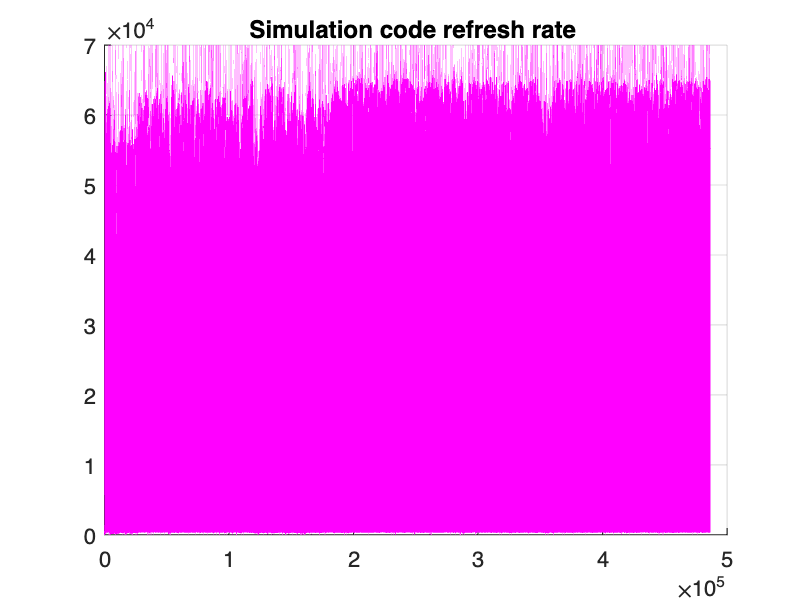


figure(8),clf,grid,hold on
title('Simulation code refresh rate ')
plot(linspace(1,k,k),hzGraph(1:k),'m-')


disp(['Time taken to run simulation code: ', num2str(EKFTotalTime), ' seconds for ', num2str(k),' iterations'])

Time taken to run simulation code: 25 seconds for 486333 iterations


hz_average = k/EKFTotalTime;
disp(['Average refresh rate of code: ', num2str(hz_average), ' hz'])

Average refresh rate of code: 19453.3108 hz



IterationBetweenObservations = zeros(n,1);
for i = 2:n
    IterationBetweenObservations(i) = kCheck(i) - kCheck(i-1);
end
AvgIter = mean(IterationBetweenObservations);
disp(['Average iterations between next observation iteration: ',num2str(AvgIter)])

Average iterations between next observation iteration: 77.405


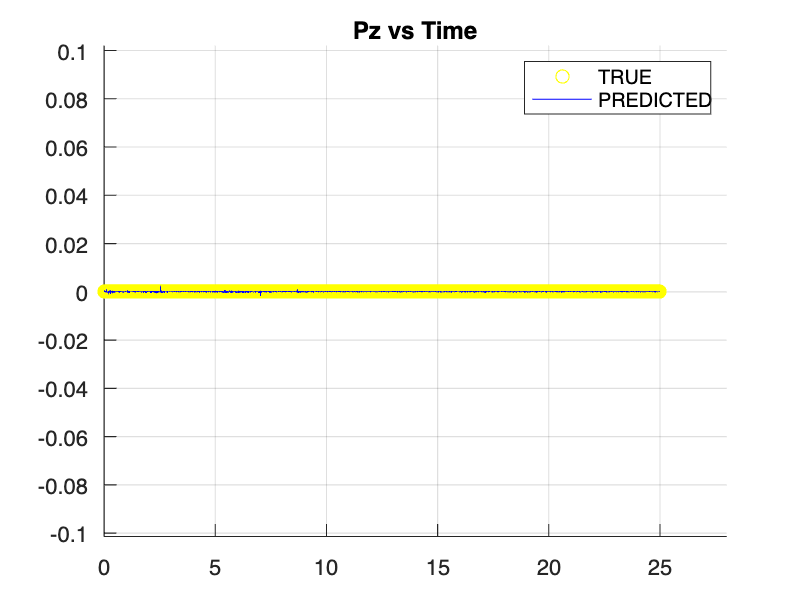

figure(8),clf,grid,hold on
title('Open Loop Iterations Between Observations')
plot(linspace(1,n,n),IterationBetweenObservations,'c-')

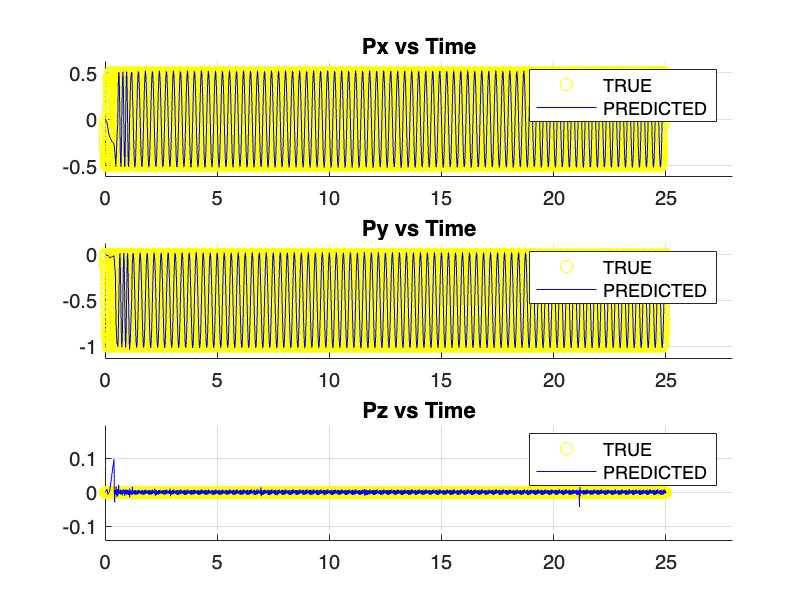

% Create a new figure
i = 5001;
figure('Name', 'Position vs Time Plots'), clf

% Subplot for Xk's X position vs time
subplot(3, 1, 1), grid, hold on
title('Px vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,p_x(1:i-1),'yo')
plot(tGraph(1:length(XGraph)),XGraph,'b-')
axis([0 tGraph(end)+3 min(XGraph)-0.1 max(XGraph)+0.1])
legend('TRUE','PREDICTED')

subplot(3, 1, 2), grid, hold on
title('Py vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,p_y(1:i-1),'yo')
plot(tGraph(1:length(YGraph)),YGraph,'b-')
axis([0 (tGraph(end)+3) (min(YGraph)-0.1) (max(YGraph)+0.1)])
legend('TRUE','PREDICTED')

subplot(3, 1, 3), grid, hold on
title('Pz vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,p_z(1:i-1),'yo')
plot(tGraph(1:length(ZGraph)),ZGraph,'b-')
axis([0 (tGraph(end)+3) (min(ZGraph)-0.1) (max(ZGraph)+0.1)])
legend('TRUE','PREDICTED')

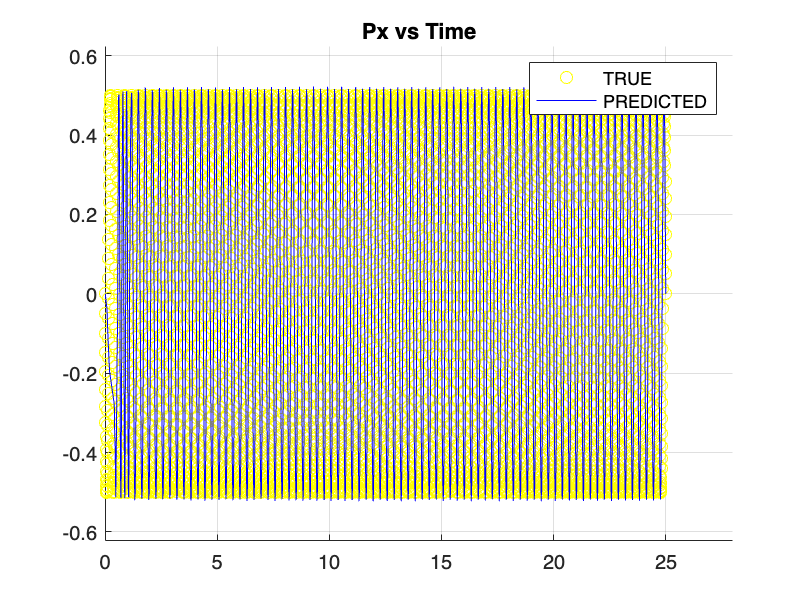


figure(1),clf,grid,hold on
title('Px vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,p_x(1:i-1),'yo')
plot(tGraph(1:length(XGraph)),XGraph,'b-')
axis([0 tGraph(end)+3 min(XGraph)-0.1 max(XGraph)+0.1])
legend('TRUE','PREDICTED')


xPos_enc_interp = interp1(linspace(1,i-1,i-1)*observationInterval,p_x(1:i-1),tGraph(1:length(XGraph)),'linear','extrap');
validIdx = ~isnan(XGraph);
rmse_x = sqrt(mean((XGraph(validIdx) - xPos_enc_interp(validIdx)).^2))

rmse_x = 0.0135

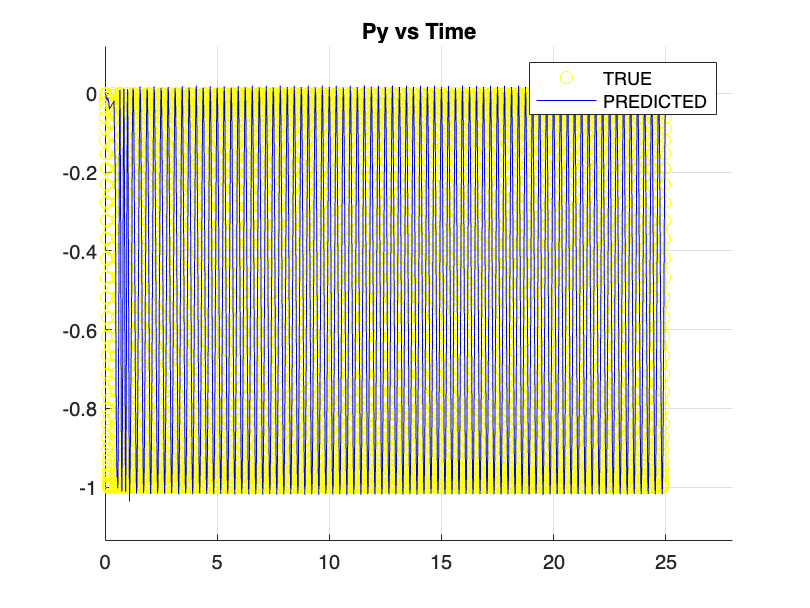


figure(2),clf,grid, hold on
title('Py vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,p_y(1:i-1),'yo')
plot(tGraph(1:length(YGraph)),YGraph,'b-')
axis([0 (tGraph(end)+3) (min(YGraph)-0.1) (max(YGraph)+0.1)])
legend('TRUE','PREDICTED')

disp(Xk(2))

    0.0032



YGraph'

ans =          0   -0.0183   -0.0115   -0.0222   -0.0402   -0.0192   -0.0803   -0.1254   -0.1586   -0.1909   -0.2300   -0.2726   -0.3181   -0.3649   -0.4150   -0.4616   -0.5117   -0.5693   -0.6210   -0.6696   -0.7151   -0.7766   -0.8084   -0.8356   -0.8723   -0.9078   -0.9297   -0.9665   -0.9739   -0.9784   -0.9882   -0.9948   -1.0024   -0.9949   -0.9870   -0.9704   -0.9477   -0.9275   -0.8979   -0.8625   -0.8300   -0.7864   -0.7407   -0.6935   -0.6303   -0.5947   -0.5508   -0.4960   -0.4470   -0.3946


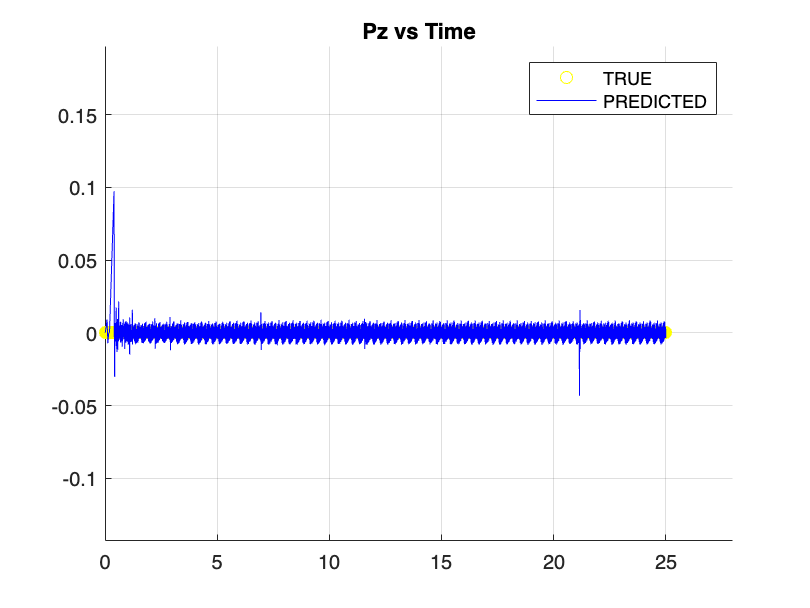


figure(3),clf,grid, hold on
title('Pz vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,p_z(1:i-1),'yo')
plot(tGraph(1:length(ZGraph)),ZGraph,'b-')
axis([0 (tGraph(end)+3) (min(ZGraph)-0.1) (max(ZGraph)+0.1)])
legend('TRUE','PREDICTED')

disp(Xk(3))

  -7.5820e-04



ZGraph'

ans =          0    0.0092   -0.0071   -0.0004    0.0010    0.0973   -0.0027   -0.0304    0.0064   -0.0013    0.0027   -0.0013    0.0065   -0.0012   -0.0016    0.0057   -0.0034   -0.0058    0.0067   -0.0026   -0.0009    0.0174   -0.0091   -0.0018   -0.0040   -0.0029   -0.0048   -0.0132   -0.0029    0.0095    0.0066   -0.0115   -0.0004    0.0015   -0.0045    0.0001    0.0048   -0.0048   -0.0019   -0.0045   -0.0055    0.0064   -0.0038   -0.0059    0.0216   -0.0024    0.0053   -0.0017   -0.0013    0.0048


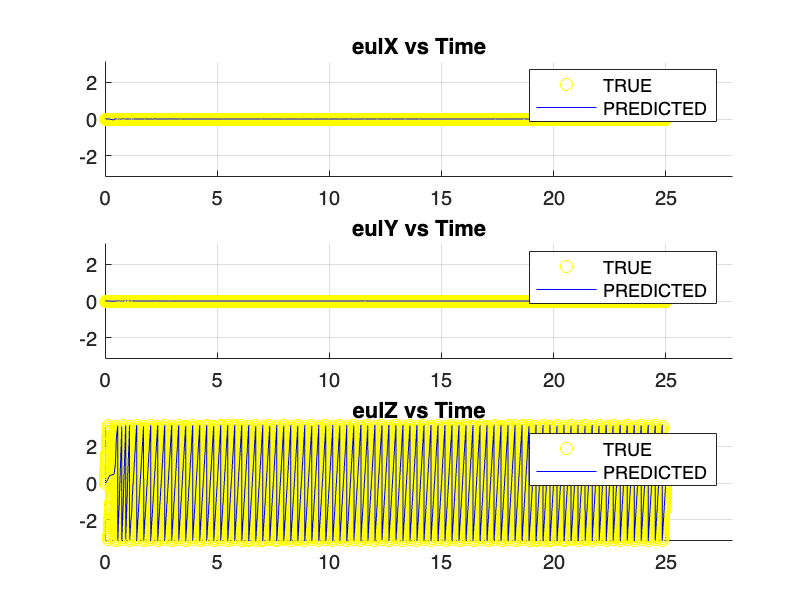


figure('Name', 'Rotation vs Time Plots'), clf
subplot(3, 1, 1), grid, hold on
title('eulX vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,3),'yo')
plot(tGraph(1:length(eulxGraph)),eulxGraph,'b-')
axis([0 (tGraph(end)+3) -pi pi])
legend('TRUE','PREDICTED')

subplot(3, 1, 2), grid, hold on
title('eulY vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,2),'yo')
plot(tGraph(1:length(eulyGraph)),eulyGraph,'b-')
axis([0 (tGraph(end)+3) -pi pi])
legend('TRUE','PREDICTED')

subplot(3, 1, 3), grid, hold on
title('eulZ vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,1),'yo')
plot(tGraph(1:length(eulzGraph)),eulzGraph,'b-')
axis([0 (tGraph(end)+3) -pi pi])
legend('TRUE','PREDICTED')

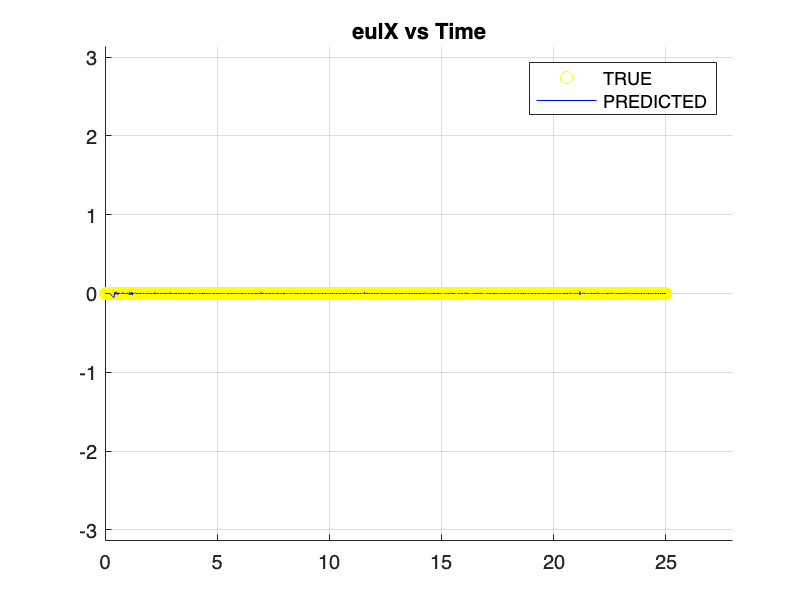


figure(4),clf,grid,hold on
title('eulX vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,3),'yo')
plot(tGraph(1:length(eulxGraph)),eulxGraph,'b-')
axis([0 (tGraph(end)+3) -pi pi])
legend('TRUE','PREDICTED')

disp(eulZYX(1))

   -0.0021



eulxGraph'

ans =          0   -0.0014   -0.0014   -0.0001   -0.0000   -0.0553   -0.0058    0.0167    0.0072    0.0038    0.0104   -0.0058    0.0048   -0.0119   -0.0040    0.0144    0.0025    0.0028    0.0016    0.0009    0.0015    0.0219    0.0213   -0.0010    0.0064   -0.0034   -0.0046    0.0000   -0.0121    0.0081   -0.0027   -0.0122   -0.0095    0.0096   -0.0081   -0.0034   -0.0021   -0.0069   -0.0013   -0.0085   -0.0058    0.0063   -0.0039   -0.0025    0.0096    0.0060   -0.0081   -0.0006    0.0008    0.0052


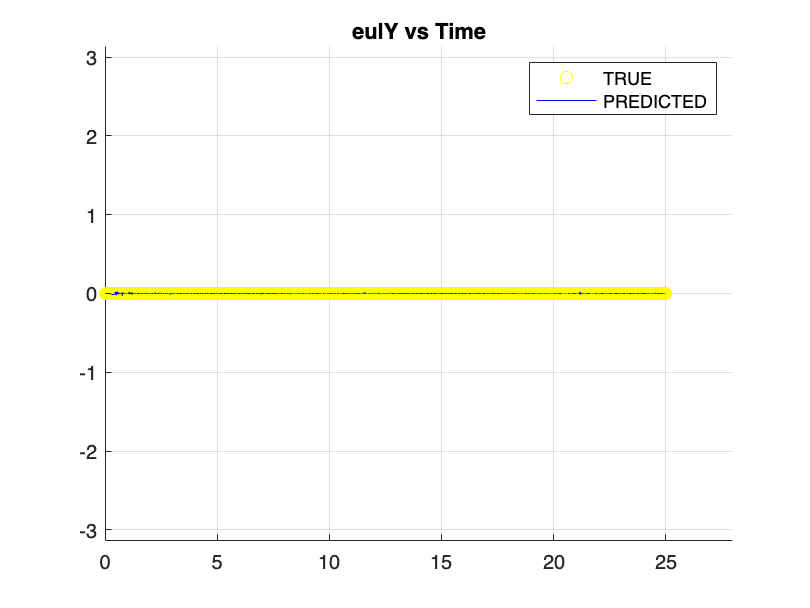


figure(5),clf,grid,hold on
title('eulY vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,2),'yo')
plot(tGraph(1:length(eulyGraph)),eulyGraph,'b-')
axis([0 (tGraph(end)+3) -pi pi])
legend('TRUE','PREDICTED')

disp(eulZYX(2))

   2.0672e-04



eulyGraph'

ans =          0   -0.0003    0.0012   -0.0003    0.0000   -0.0189   -0.0106   -0.0007   -0.0040   -0.0006    0.0217   -0.0084   -0.0167    0.0094    0.0013    0.0003   -0.0086   -0.0095    0.0097    0.0007   -0.0031    0.0132    0.0228   -0.0209   -0.0010    0.0041    0.0004    0.0084    0.0012    0.0231    0.0068    0.0042   -0.0077   -0.0055   -0.0140   -0.0081    0.0189   -0.0012   -0.0043   -0.0054   -0.0068    0.0039   -0.0027   -0.0022   -0.0025    0.0079   -0.0013    0.0044    0.0048    0.0109


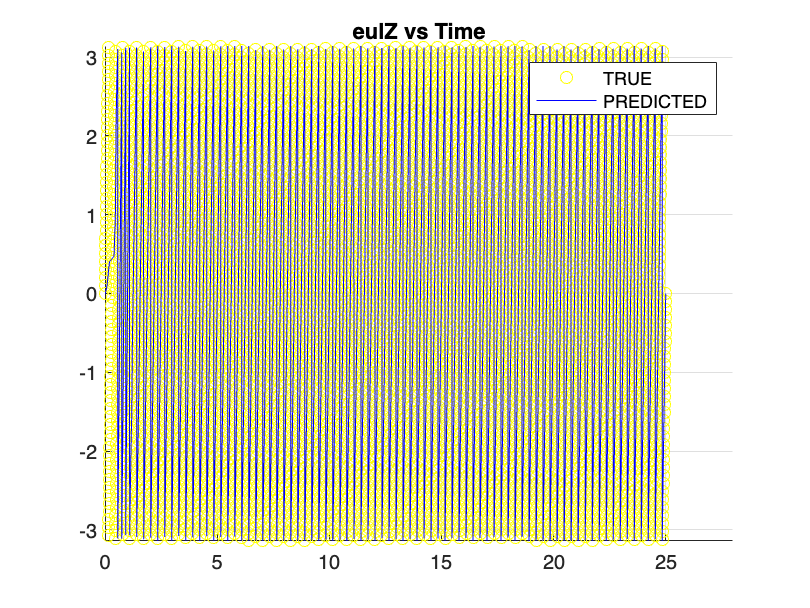


figure(6),clf,grid,hold on
title('eulZ vs Time')
plot(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,1),'yo')
plot(tGraph(1:length(eulzGraph)),eulzGraph,'b-')
axis([0 (tGraph(end)+3) -pi pi])
legend('TRUE','PREDICTED')

disp(eulZYX(3))

   9.4863e-05



eulzGraph'

ans =          0    0.0985    0.2004    0.3014    0.4021    0.4715    0.6019    0.7048    0.8074    0.9057    0.9847    1.0606    1.1666    1.2754    1.3720    1.4729    1.5662    1.6711    1.7804    1.8825    1.9903    2.1883    2.2902    2.3588    2.4473    2.5292    2.6107    2.7367    2.8316    2.9586    3.0203    3.1033   -3.1087   -3.0042   -2.9023   -2.8084   -2.6889   -2.5953   -2.5014   -2.3890   -2.2935   -2.1829   -2.0792   -1.9733   -1.8242   -1.7051   -1.6293   -1.5420   -1.4534   -1.3656


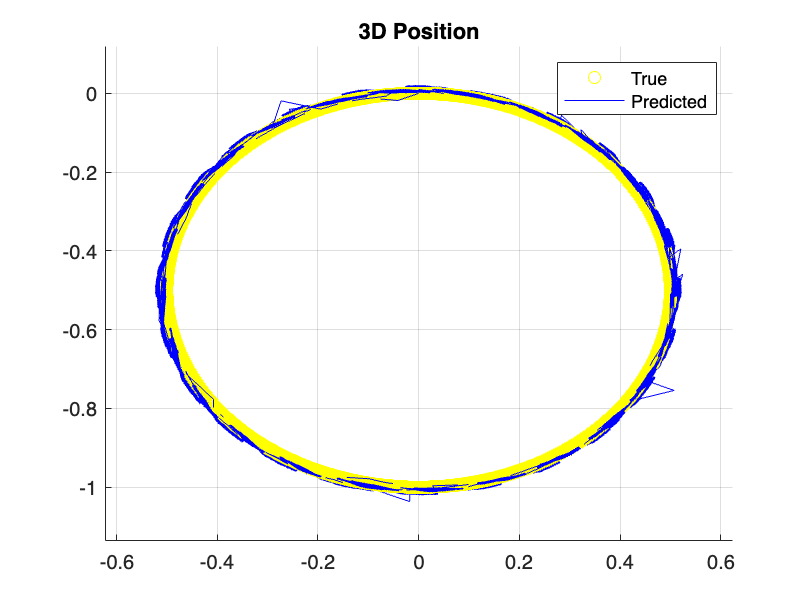


figure(7), clf, grid, hold on
plot3(p_x,p_y,p_z,'yo')
plot3(XGraph,YGraph,ZGraph,'b-')
title('3D Position')
legend('True','Predicted')
axis([min(XGraph)-0.1 max(XGraph)+0.1 min(YGraph)-0.1 max(YGraph)+0.1 min(ZGraph)-0.1 max(ZGraph)+0.1])
view(2)

xPos_enc_interp = interp1(linspace(1,i-1,i-1)*observationInterval,p_x(1:i-1),tGraph(1:length(XGraph)),'linear','extrap');
validIdx = 1000:length(XGraph);
rmse_x = sqrt(mean((XGraph(validIdx) - xPos_enc_interp(validIdx)).^2))

rmse_x = 0.0104


yPos_enc_interp = interp1(linspace(1,i-1,i-1)*observationInterval,p_y(1:i-1),tGraph(1:length(XGraph)),'linear','extrap');
validIdx = 1000:100000;
rmse_y = sqrt(mean((YGraph(validIdx) - yPos_enc_interp(validIdx)).^2))

rmse_y = 0.0088


zPos_enc_interp = interp1(linspace(1,i-1,i-1)*observationInterval,p_z(1:i-1),tGraph(1:length(XGraph)),'linear','extrap');
validIdx = ~isnan(ZGraph);
rmse_z = sqrt(mean((ZGraph(validIdx) - zPos_enc_interp(validIdx)).^2))

rmse_z = 0.0042


rmse_3D = norm([rmse_x rmse_y rmse_z])

rmse_3D = 0.0142

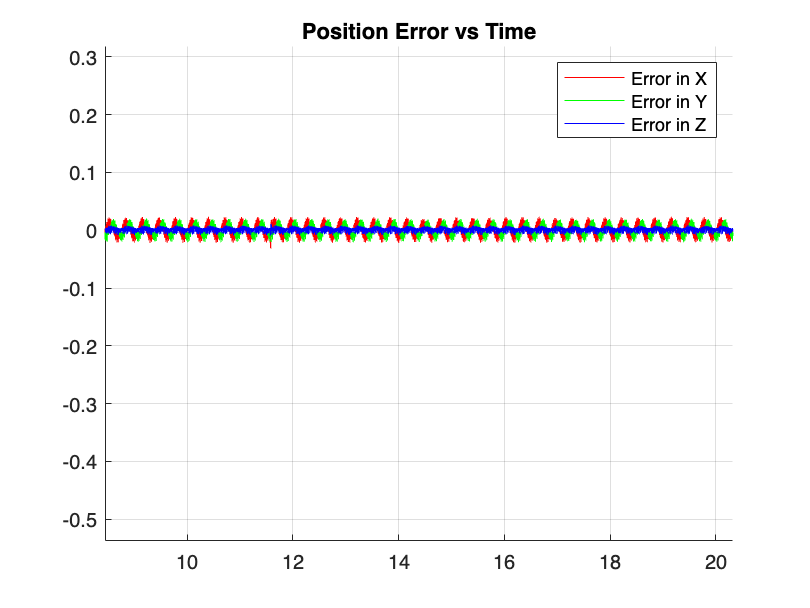


figure(2),clf,grid, hold on
title('Position Error vs Time')
plot(tGraph,(xPos_enc_interp-XGraph),'r-')
plot(tGraph,(yPos_enc_interp-YGraph),'g-')
plot(tGraph,(zPos_enc_interp-ZGraph),'b-')
axis([0 (tGraph(end)+3) (min(xPos_enc_interp-XGraph)-0.05) (max(xPos_enc_interp-XGraph)+0.05)])
legend('Error in X','Error in Y','Error in Z')


xPos_enc_interp = interp1(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,3),tGraph(1:length(XGraph)),'linear','extrap');
validIdx = 1000:length(XGraph);
rmse_eulx = sqrt(mean((eulxGraph(validIdx) - xPos_enc_interp(validIdx)).^2))

rmse_eulx = 0.0016


yPos_enc_interp = interp1(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,2),tGraph(1:length(XGraph)),'linear','extrap');
validIdx = 1000:length(XGraph);
rmse_euly = sqrt(mean((eulyGraph(validIdx) - yPos_enc_interp(validIdx)).^2))

rmse_euly = 0.0016


zPos_enc_interp = interp1(linspace(1,i-1,i-1)*observationInterval,eulZYX_true(1:i-1,1),tGraph(1:length(XGraph)),'linear','extrap');
validIdx = 1:100000;%~isnan(ZGraph);
rmse_eulz = sqrt(mean((eulzGraph(validIdx) - zPos_enc_interp(validIdx)).^2))

rmse_eulz = 0.2160


rmse_eul3D = norm([rmse_eulx rmse_euly rmse_eulz])

rmse_eul3D = 0.2160

rmse_eul3D_deg = rad2deg(rmse_eul3D)

rmse_eul3D_deg = 12.3773

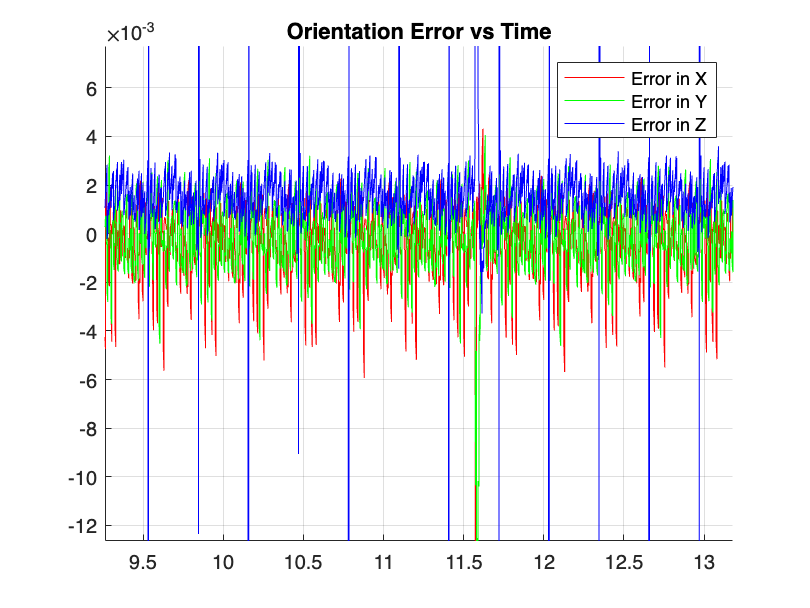


figure(2),clf,grid, hold on
title('Orientation Error vs Time')
plot(tGraph,(xPos_enc_interp-eulxGraph),'r-')
plot(tGraph,(yPos_enc_interp-eulyGraph),'g-')
plot(tGraph,(zPos_enc_interp-eulzGraph),'b-')
axis([0 (tGraph(end)+3) (min(zPos_enc_interp-eulzGraph)-0.05) (max(zPos_enc_interp-eulzGraph)+0.05)])
legend('Error in X','Error in Y','Error in Z')

camTestPlot(UV_C1_PREV,isOpenMV1,camID1)
UV_1 = UV_prevSORT(UV_1_SCRAM,UV_C1_PREV,isOpenMV1);
camTestPlot(UV_1,isOpenMV1,camID1)

camTestPlot(UV_C2_PREV,isOpenMV2,camID2)
UV_2 = UV_prevSORT(UV_2_SCRAM,UV_C2_PREV,isOpenMV2);
camTestPlot(UV_2,isOpenMV2,camID2)

camTestPlot(UV_C3_PREV,isOpenMV3,camID3)
UV_3 = UV_prevSORT(UV_3_SCRAM,UV_C3_PREV,isOpenMV3);
camTestPlot(UV_3,isOpenMV3,camID3)

camTestPlot(UV_C4_PREV,isOpenMV4,camID4)
UV_4 = UV_prevSORT(UV_4_SCRAM,UV_C4_PREV,isOpenMV4);
camTestPlot(UV_4,isOpenMV4,camID4)

camTestPlot(UV_C5_PREV,isOpenMV5,camID5)
UV_5 = UV_prevSORT(UV_5_SCRAM,UV_C5_PREV,isOpenMV5);
camTestPlot(UV_5,isOpenMV5,camID5)

camTestPlot(UV_C6_PREV,isOpenMV6,camID6)
UV_6 = UV_prevSORT(UV_6_SCRAM,UV_C6_PREV,isOpenMV6);
camTestPlot(UV_6,isOpenMV6,camID6)


A = [1, 2; 3, 4; 5, 6];
tic;
B = reshape(A', [], 1);
dT1 = toc;
pause(1);
tic;
A = A';
B = A(:);
dT2 = toc;

norm(Xk(1:3))

function error = computeReprojectionError(pose, worldPoints, imagePoints, cParams)
    % Decompose Pose Parameters
    rotationVector = pose(1:3);
    translationVector = pose(4:6);

    % Project World Points to Image Plane using estimated pose
    projectedPoints = world2img(worldPoints, rigidtform3d([eul2rotm(rotationVector) translationVector'; 0 0 0 1]), cParams.Intrinsics);

    % Compute Reprojection Error
    error = projectedPoints - imagePoints;
    error = error(:); % Reshape to a vector for lsqnonlin
end

function F = FMat(cInt1,cInt2,camPose_1,camPose_2)
    %DRAWS LINE FROM 1 (U,V) ONTO 2: (therefore, 2 will have the epipolar
    %line from and CAM 1 will be master CAM).
    %______________________________
    K1 = cInt1.K; % Intrinsic matrix of Camera 1
    K2 = cInt2.K; % Intrinsic matrix of Camera 2
    R1 = camPose_1.R; % Rotation matrix of Camera 1 w.r.t world frame
    R2 = camPose_2.R; % Rotation matrix of Camera 2 w.r.t world frame
    t1 = camPose_1.Translation'; % Translation vector of Camera 1 w.r.t world frame
    t2 = camPose_2.Translation'; % Translation vector of Camera 2 w.r.t world frame
    % Compute the essential matrix
    R = R2' * R1; % Relative rotation between Camera 1 and Camera 2
    t = R2'*(t2 - t1);  % Relative translation between Camera 1 and Camera 2
    T_x = [0 -t(3) t(2); t(3) 0 -t(1); -t(2) t(1) 0]; % Skew-symmetric matrix of t
    E = T_x * R; % Essential matrix

    % Compute the fundamental matrix
    F = K2' \ E / K1; % Fundamental matrix
end

function sendREADY(openmv);
    flush(openmv);
    openmv.write('READY','string');
end
function [UV, bOpenMV] = captureData(openmv,cameraParams)
    % Send a command to the camera to signal readiness
    % tic;
    % flush(openmv);
    % openmv.write('READY','string');
    % Initialize output
    cam_data = [];
    bOpenMV = false; % Use 'false' instead of 'False' in MATLAB

    % Set a timeout for readline operation (adjust the timeout value as needed)
    openmv.Timeout = 1/20; % Timeout in seconds
    
    try 
        % Attempt to read data from the camera
        data_str = openmv.readline();
        % If data is successfully read, split and convert it to double
        cam_data = str2double(split(data_str,','));
        UV = undistortPoints([cam_data(1) cam_data(2); cam_data(3) cam_data(4); cam_data(5) cam_data(6)],cameraParams);
        % disp(data_str)
        % If data is received, set boolean to true
        bOpenMV = true;
        % dT = toc;
        % disp(1/dT)
    catch ME
        % disp('Error occurred:');
        % disp(ME.message);
        UV = [];
        bOpenMV = false;
    end
end

function UV = UV_prevSORT(UV_SCRAM,UV_Prev,bOpenMV)
    if bOpenMV
        UV_sorted = zeros(3,2);
        for k = 1:3 
            distance = zeros(3,1);
            for i = 1:3
                distance(i,:) = norm(abs(UV_Prev(k,:) - UV_SCRAM(i,:)));
            end
            [~,pos] = min(distance);
            UV_sorted(k,:) = UV_SCRAM(pos,:);
        end
        UV = UV_sorted;
    else
        UV = [];
    end
end


function H = HCreate(C1,Xkp,bOpenMV,f2b_1,f2b_2,f2b_3)
    if bOpenMV
        H = [C1(1,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(1,2)*(2*f2b_1(3) + 4*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(1,3)*(4*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8) - 2*f2b_1(1)*Xkp(9)) + C1(1,1)*(4*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9) - 2*f2b_1(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(3) + 4*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(3,3)*(4*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8) - 2*f2b_1(1)*Xkp(9)) + C1(3,1)*(4*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9) - 2*f2b_1(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,3)*(2*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(1,1)*(4*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 2*f2b_1(3)*Xkp(10)) + 2*C1(1,2)*f2b_1(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(3,1)*(4*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 2*f2b_1(3)*Xkp(10)) + 2*C1(3,2)*f2b_1(1)*Xkp(9))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_1(1)*Xkp(8) + 4*f2b_1(2)*Xkp(9) + f2b_1(3)*(2*Xkp(10) + 2)) + C1(1,1)*(2*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8)) - C1(1,3)*(2*f2b_1(1)*Xkp(7) - 2*f2b_1(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(1)*Xkp(8) + 4*f2b_1(2)*Xkp(9) + f2b_1(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8)) - C1(3,3)*(2*f2b_1(1)*Xkp(7) - 2*f2b_1(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9)) - C1(1,1)*(2*f2b_1(2)*Xkp(7) - 2*f2b_1(3)*Xkp(8)) + C1(1,3)*(2*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 4*f2b_1(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9)) - C1(3,1)*(2*f2b_1(2)*Xkp(7) - 2*f2b_1(3)*Xkp(8)) + C1(3,3)*(2*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 4*f2b_1(3)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0; 
             C1(2,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(2,2)*(2*f2b_1(3) + 4*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(2,3)*(4*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8) - 2*f2b_1(1)*Xkp(9)) + C1(2,1)*(4*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9) - 2*f2b_1(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(3) + 4*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(3,3)*(4*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8) - 2*f2b_1(1)*Xkp(9)) + C1(3,1)*(4*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9) - 2*f2b_1(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,3)*(2*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(2,1)*(4*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 2*f2b_1(3)*Xkp(10)) + 2*C1(2,2)*f2b_1(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_1(2)*Xkp(7) + 2*f2b_1(1)*Xkp(10)) + C1(3,1)*(4*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 2*f2b_1(3)*Xkp(10)) + 2*C1(3,2)*f2b_1(1)*Xkp(9))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_1(1)*Xkp(8) + 4*f2b_1(2)*Xkp(9) + f2b_1(3)*(2*Xkp(10) + 2)) + C1(2,1)*(2*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8)) - C1(2,3)*(2*f2b_1(1)*Xkp(7) - 2*f2b_1(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(1)*Xkp(8) + 4*f2b_1(2)*Xkp(9) + f2b_1(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_1(3)*Xkp(7) + 2*f2b_1(2)*Xkp(8)) - C1(3,3)*(2*f2b_1(1)*Xkp(7) - 2*f2b_1(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9)) - C1(2,1)*(2*f2b_1(2)*Xkp(7) - 2*f2b_1(3)*Xkp(8)) + C1(2,3)*(2*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 4*f2b_1(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_1(1)*Xkp(7) + 2*f2b_1(3)*Xkp(9)) - C1(3,1)*(2*f2b_1(2)*Xkp(7) - 2*f2b_1(3)*Xkp(8)) + C1(3,3)*(2*f2b_1(1)*Xkp(8) + 2*f2b_1(2)*Xkp(9) + 4*f2b_1(3)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_1(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_1(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_1(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_1(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_1(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_1(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_1(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_1(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0;
             C1(1,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(1,2)*(2*f2b_2(3) + 4*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(1,3)*(4*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8) - 2*f2b_2(1)*Xkp(9)) + C1(1,1)*(4*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9) - 2*f2b_2(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(3) + 4*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(3,3)*(4*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8) - 2*f2b_2(1)*Xkp(9)) + C1(3,1)*(4*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9) - 2*f2b_2(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,3)*(2*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(1,1)*(4*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 2*f2b_2(3)*Xkp(10)) + 2*C1(1,2)*f2b_2(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(3,1)*(4*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 2*f2b_2(3)*Xkp(10)) + 2*C1(3,2)*f2b_2(1)*Xkp(9))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_2(1)*Xkp(8) + 4*f2b_2(2)*Xkp(9) + f2b_2(3)*(2*Xkp(10) + 2)) + C1(1,1)*(2*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8)) - C1(1,3)*(2*f2b_2(1)*Xkp(7) - 2*f2b_2(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(1)*Xkp(8) + 4*f2b_2(2)*Xkp(9) + f2b_2(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8)) - C1(3,3)*(2*f2b_2(1)*Xkp(7) - 2*f2b_2(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9)) - C1(1,1)*(2*f2b_2(2)*Xkp(7) - 2*f2b_2(3)*Xkp(8)) + C1(1,3)*(2*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 4*f2b_2(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9)) - C1(3,1)*(2*f2b_2(2)*Xkp(7) - 2*f2b_2(3)*Xkp(8)) + C1(3,3)*(2*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 4*f2b_2(3)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0; 
             C1(2,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(2,2)*(2*f2b_2(3) + 4*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(2,3)*(4*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8) - 2*f2b_2(1)*Xkp(9)) + C1(2,1)*(4*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9) - 2*f2b_2(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(3) + 4*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(3,3)*(4*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8) - 2*f2b_2(1)*Xkp(9)) + C1(3,1)*(4*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9) - 2*f2b_2(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,3)*(2*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(2,1)*(4*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 2*f2b_2(3)*Xkp(10)) + 2*C1(2,2)*f2b_2(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_2(2)*Xkp(7) + 2*f2b_2(1)*Xkp(10)) + C1(3,1)*(4*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 2*f2b_2(3)*Xkp(10)) + 2*C1(3,2)*f2b_2(1)*Xkp(9))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_2(1)*Xkp(8) + 4*f2b_2(2)*Xkp(9) + f2b_2(3)*(2*Xkp(10) + 2)) + C1(2,1)*(2*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8)) - C1(2,3)*(2*f2b_2(1)*Xkp(7) - 2*f2b_2(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(1)*Xkp(8) + 4*f2b_2(2)*Xkp(9) + f2b_2(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_2(3)*Xkp(7) + 2*f2b_2(2)*Xkp(8)) - C1(3,3)*(2*f2b_2(1)*Xkp(7) - 2*f2b_2(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9)) - C1(2,1)*(2*f2b_2(2)*Xkp(7) - 2*f2b_2(3)*Xkp(8)) + C1(2,3)*(2*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 4*f2b_2(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_2(1)*Xkp(7) + 2*f2b_2(3)*Xkp(9)) - C1(3,1)*(2*f2b_2(2)*Xkp(7) - 2*f2b_2(3)*Xkp(8)) + C1(3,3)*(2*f2b_2(1)*Xkp(8) + 2*f2b_2(2)*Xkp(9) + 4*f2b_2(3)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_2(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_2(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_2(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_2(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_2(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_2(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_2(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_2(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0; 
             C1(1,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(1,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(1,2)*(2*f2b_3(3) + 4*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(1,3)*(4*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8) - 2*f2b_3(1)*Xkp(9)) + C1(1,1)*(4*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9) - 2*f2b_3(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(3) + 4*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(3,3)*(4*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8) - 2*f2b_3(1)*Xkp(9)) + C1(3,1)*(4*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9) - 2*f2b_3(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,3)*(2*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(1,1)*(4*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 2*f2b_3(3)*Xkp(10)) + 2*C1(1,2)*f2b_3(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(3,1)*(4*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 2*f2b_3(3)*Xkp(10)) + 2*C1(3,2)*f2b_3(1)*Xkp(9))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_3(1)*Xkp(8) + 4*f2b_3(2)*Xkp(9) + f2b_3(3)*(2*Xkp(10) + 2)) + C1(1,1)*(2*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8)) - C1(1,3)*(2*f2b_3(1)*Xkp(7) - 2*f2b_3(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(1)*Xkp(8) + 4*f2b_3(2)*Xkp(9) + f2b_3(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8)) - C1(3,3)*(2*f2b_3(1)*Xkp(7) - 2*f2b_3(2)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(1,2)*(2*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9)) - C1(1,1)*(2*f2b_3(2)*Xkp(7) - 2*f2b_3(3)*Xkp(8)) + C1(1,3)*(2*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 4*f2b_3(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9)) - C1(3,1)*(2*f2b_3(2)*Xkp(7) - 2*f2b_3(3)*Xkp(8)) + C1(3,3)*(2*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 4*f2b_3(3)*Xkp(10)))*(C1(1,4) + C1(1,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(1,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(1,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0; 
             C1(2,1)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,1)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,2)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,2)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, C1(2,3)/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - (C1(3,3)*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0, (C1(2,2)*(2*f2b_3(3) + 4*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(2,3)*(4*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8) - 2*f2b_3(1)*Xkp(9)) + C1(2,1)*(4*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9) - 2*f2b_3(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(3) + 4*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(3,3)*(4*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8) - 2*f2b_3(1)*Xkp(9)) + C1(3,1)*(4*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9) - 2*f2b_3(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,3)*(2*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(2,1)*(4*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 2*f2b_3(3)*Xkp(10)) + 2*C1(2,2)*f2b_3(1)*Xkp(9))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,3)*(2*f2b_3(2)*Xkp(7) + 2*f2b_3(1)*Xkp(10)) + C1(3,1)*(4*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 2*f2b_3(3)*Xkp(10)) + 2*C1(3,2)*f2b_3(1)*Xkp(9))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_3(1)*Xkp(8) + 4*f2b_3(2)*Xkp(9) + f2b_3(3)*(2*Xkp(10) + 2)) + C1(2,1)*(2*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8)) - C1(2,3)*(2*f2b_3(1)*Xkp(7) - 2*f2b_3(2)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(1)*Xkp(8) + 4*f2b_3(2)*Xkp(9) + f2b_3(3)*(2*Xkp(10) + 2)) + C1(3,1)*(2*f2b_3(3)*Xkp(7) + 2*f2b_3(2)*Xkp(8)) - C1(3,3)*(2*f2b_3(1)*Xkp(7) - 2*f2b_3(2)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, (C1(2,2)*(2*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9)) - C1(2,1)*(2*f2b_3(2)*Xkp(7) - 2*f2b_3(3)*Xkp(8)) + C1(2,3)*(2*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 4*f2b_3(3)*Xkp(10)))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))) - ((C1(3,2)*(2*f2b_3(1)*Xkp(7) + 2*f2b_3(3)*Xkp(9)) - C1(3,1)*(2*f2b_3(2)*Xkp(7) - 2*f2b_3(3)*Xkp(8)) + C1(3,3)*(2*f2b_3(1)*Xkp(8) + 2*f2b_3(2)*Xkp(9) + 4*f2b_3(3)*Xkp(10)))*(C1(2,4) + C1(2,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(2,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(2,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9)))))/(C1(3,4) + C1(3,1)*(Xkp(1) + f2b_3(1)*(2*Xkp(7)^2 + 2*Xkp(8)^2 - 1) - f2b_3(2)*(2*Xkp(7)*Xkp(10) - 2*Xkp(8)*Xkp(9)) + f2b_3(3)*(2*Xkp(7)*Xkp(9) + 2*Xkp(8)*Xkp(10))) + C1(3,3)*(Xkp(3) + f2b_3(3)*(2*Xkp(7)^2 + 2*Xkp(10)^2 - 1) - f2b_3(1)*(2*Xkp(7)*Xkp(9) - 2*Xkp(8)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)*Xkp(8) + 2*Xkp(9)*Xkp(10))) + C1(3,2)*(Xkp(2) + f2b_3(3)*(2*Xkp(7) + 2*Xkp(9) + 2*Xkp(9)*Xkp(10)) + f2b_3(2)*(2*Xkp(7)^2 + 2*Xkp(9)^2 - 1) + f2b_3(1)*(2*Xkp(7)*Xkp(10) + 2*Xkp(8)*Xkp(9))))^2, 0, 0, 0]; 
    else
        H = [];
    end
end

function R = createR(b1,b2,b3,b4,b5,b6)
    n=0;
    if b1
        n=n+1;
    end
    if b2
        n=n+1;
    end
    if b3
        n=n+1;
    end
    if b4
        n=n+1;
    end
    if b5
        n=n+1;
    end
    if b6
        n=n+1;
    end
    R = eye(6*n);
end

function Yk = createYk(UV_1,UV_2,UV_3,UV_4,UV_5,UV_6,b1,b2,b3,b4,b5,b6)
    if b1
        Yk_UV1 = [UV_1(1,:)';UV_1(2,:)';UV_1(3,:)'];
    else
        Yk_UV1 = [];
    end
    if b2
        Yk_UV2 = [UV_2(1,:)';UV_2(2,:)';UV_2(3,:)'];
    else
        Yk_UV2 = [];
    end
    if b3
        Yk_UV3 = [UV_3(1,:)';UV_3(2,:)';UV_3(3,:)'];
    else
        Yk_UV3 = [];
    end
    if b4
        Yk_UV4 = [UV_4(1,:)';UV_4(2,:)';UV_4(3,:)'];
    else
        Yk_UV4 = [];
    end
    if b5
        Yk_UV5 = [UV_5(1,:)';UV_5(2,:)';UV_5(3,:)'];
    else
        Yk_UV5 = [];
    end
    if b6
        Yk_UV6 = [UV_6(1,:)';UV_6(2,:)';UV_6(3,:)'];
    else
        Yk_UV6 = [];
    end
    Yk = [Yk_UV1;Yk_UV2;Yk_UV3;Yk_UV4;Yk_UV5;Yk_UV6];
end

function [HXkp,HXkp_32] = createHXkp(Xkp,R_QUAT,f2b_1,f2b_2,f2b_3, extrinsics, cameraParams, isOpenMV)
    if isOpenMV
        HXkp_32 = world2img([(Xkp(1:3)+R_QUAT*f2b_1)';(Xkp(1:3)+R_QUAT*f2b_2)';(Xkp(1:3)+R_QUAT*f2b_3)'],rigidtform3d(extrinsics),cameraParams);
        HXkp_23 = HXkp_32';
        HXkp = HXkp_23(:);
    else
        HXkp_32 = world2img([(Xkp(1:3)+R_QUAT*f2b_1)';(Xkp(1:3)+R_QUAT*f2b_2)';(Xkp(1:3)+R_QUAT*f2b_3)'],rigidtform3d(extrinsics),cameraParams);
        HXkp = [];
    end
end

function camTestPlot(UV_C1,bOpenMV,camID)
    % Camera 2's image dimensions - replace with actual values
    imageWidthC1 = 640;  % Width of Camera 2's image
    imageHeightC1= 480; % Height of Camera 2's image
    if bOpenMV
        figure;
        hold on;
        axis([1 imageWidthC1 1 imageHeightC1]);
        xlabel('X-axis (pixels)');
        ylabel('Y-axis (pixels)');
        title('Camera '+camID+' Image Plane with Epipolar Line (DATA UNSCAMBLED)');

        % Plot the feature point in Camera 2
        plot(UV_C1(1,1), UV_C1(1,2), 'ro'); % Plot as a blue circle

        % Plot the feature point in Camera 2
        plot(UV_C1(2,1), UV_C1(2,2), 'go'); % Plot as a blue circle

        % Plot the feature point in Camera 2
        plot(UV_C1(3,1), UV_C1(3,2), 'bo'); % Plot as a blue circle

        % Additional settings for the plot
        grid on;
        axis ij; % To set the origin of the image plane at the top left corner
        hold off;
    end
end
% function [UV_2,el2] = epipolarSORT(F,UV_1,UV_2_SCRAM,bOpenMV)
%    %EPIPOLAR LINES DRAWN FROM 1 onto 2:
%    %SORTS UV_2
%    % CHECK lines = epipolarLines(F,points)
%    if bOpenMV
%        el2 = zeros(3,3);
%        for k = 1:3
%            P_hom = [UV_1(k,:) 1]';
%            el2(:,k) = F*P_hom;
%            el2(:,k) = el2(:,k)/norm(el2(1:2,k));
%        end
% 
%        UV_C2 = zeros(3,2);
%        for k = 1:3
%            a = el2(1,k);
%            b = el2(2,k);
%            c = el2(3,k);
%            distance=zeros(3,1);
%            for i = 1:3
%                x0 = UV_2_SCRAM(i,1);
%                y0 = UV_2_SCRAM(i,2);
%                distance(i) = abs(a*x0 + b*y0 + c) / sqrt(a^2 + b^2);
%            end
%            [~,pos] = min(distance);
%            UV_C2(k,:) = UV_2_SCRAM(pos,:);
%        end
%        UV_2 = UV_C2;
%    else
%        UV_2 = [];
%        el2 = [];
%    end
% end

% function epipolarLineTestPlot(el1,UV_C1,bOpenMV,camID)
%     % Camera 2's image dimensions - replace with actual values
%     imageWidthC1 = 640;  % Width of Camera 2's image
%     imageHeightC1= 480; % Height of Camera 2's image
%     if bOpenMV
%         figure;
%         hold on;
%         axis([1 imageWidthC1 1 imageHeightC1]);
%         xlabel('X-axis (pixels)');
%         ylabel('Y-axis (pixels)');
%         title('Camera '+camID+' Image Plane with Epipolar Line (DATA UNSCAMBLED)');
% 
%         x = 1:imageWidthC1;
%         y = -(el1(1,1)*x + el1(3,1)) / el1(2,1);
%         plot(x, y, 'r'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C1(1,1), UV_C1(1,2), 'ro'); % Plot as a blue circle
% 
%         x = 1:imageWidthC1;
%         y = -(el1(1,2)*x + el1(3,2)) / el1(2,2);
%         plot(x, y, 'g'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C1(2,1), UV_C1(2,2), 'go'); % Plot as a blue circle
% 
%         x = 1:imageWidthC1;
%         y = -(el1(1,3)*x + el1(3,3)) / el1(2,3);
%         plot(x, y, 'b'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C1(3,1), UV_C1(3,2), 'bo'); % Plot as a blue circle
% 
%         % Additional settings for the plot
%         grid on;
%         axis ij; % To set the origin of the image plane at the top left corner
%         hold off;
%     end
% end
% 
% function epipolarLine2TestPlot(el1,UV_C1,el2,UV_C2,bOpenMV,camID)
%     % Camera 2's image dimensions - replace with actual values
%     imageWidthC1 = 640;  % Width of Camera 2's image
%     imageHeightC1= 480; % Height of Camera 2's image
%     if bOpenMV
%         figure;
%         hold on;
%         axis([1 imageWidthC1 1 imageHeightC1]);
%         xlabel('X-axis (pixels)');
%         ylabel('Y-axis (pixels)');
%         title('Camera '+camID+' Image Plane with Epipolar Line (DATA UNSCAMBLED)');
% 
%         x = 1:imageWidthC1;
%         y = -(el1(1,1)*x + el1(3,1)) / el1(2,1);
%         plot(x, y, 'r'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C1(1,1), UV_C1(1,2), 'ro'); % Plot as a blue circle
% 
%         x = 1:imageWidthC1;
%         y = -(el1(1,2)*x + el1(3,2)) / el1(2,2);
%         plot(x, y, 'g'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C1(2,1), UV_C1(2,2), 'go'); % Plot as a blue circle
% 
%         x = 1:imageWidthC1;
%         y = -(el1(1,3)*x + el1(3,3)) / el1(2,3);
%         plot(x, y, 'b'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C1(3,1), UV_C1(3,2), 'bo'); % Plot as a blue circle
% %__________________________________________
% %Epipolar Line 2
%         x = 1:imageWidthC1;
%         y = -(el2(1,1)*x + el2(3,1)) / el2(2,1);
%         plot(x, y, 'r'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C2(1,1), UV_C2(1,2), 'ro'); % Plot as a blue circle
% 
%         x = 1:imageWidthC1;
%         y = -(el2(1,2)*x + el2(3,2)) / el2(2,2);
%         plot(x, y, 'g'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C2(2,1), UV_C2(2,2), 'go'); % Plot as a blue circle
% 
%         x = 1:imageWidthC1;
%         y = -(el2(1,3)*x + el2(3,3)) / el2(2,3);
%         plot(x, y, 'b'); % Plot in red color
% 
%         % Plot the feature point in Camera 2
%         plot(UV_C2(3,1), UV_C2(3,2), 'bo'); % Plot as a blue circle
% 
%         % Additional settings for the plot
%         grid on;
%         axis ij; % To set the origin of the image plane at the top left corner
%         hold off;
%     end
% end